# 034IN "Fundamentals of Automatic Control" - Introduction to MATLAB

# Part 4L-1 - The Laplace Transform

## Introduction

In this live script, we illustrate how to use the **Matlab Symbolic Toolbox** to determine the Laplace transform of a causal function of time $f(t)$ and the inverse Laplace transform corresponding to a given rational, stricly proper or simply proper function $F(s)$ of the complex variable $s$.

The importance of managing the Laplace transform will soon become clear (refer to **Part 2** of the class material)! 

Please refer also to the [LAPLACE_TRANSFORM](https://units.sharepoint.com/:b:/r/sites/PATC_CD2024_IN03_034IN_395497/Class%20Materials/MATLAB_LIVE-SCRIPTS/LAPLACE/FUNDAMENTALS_AUTOMATIC_CONTROL_2024-2025_LAPLACE_TRANSFORM.pdf?csf=1&web=1&e=lGZaTD) document in the MS Teams course file repository.

What you will learn: 

- How to compute the Laplace transform and the inverse transform using the Symbolic Math Toolbox.

- What are the Laplace transform main properties and theorems.

## The Laplace Transform

### Introduction and Motivations

What is a **transform**?

-  A **mapping** of a mathematical **function** from one domain to another.

-  A change in perspective, not a change of the function.

Why use transforms?

- Some mathematical **problems** are **difficult to solve in their natural domain**.

-  Transform to and solve in a **new domain**, where **the problem is simplified**.

- Solved the problem in the new domain, **transform the solution back** into the original domain.

- Trade off the extra effort of transforming/inverse-transforming for simplification of the solution procedure.

- An example: the phasors method.

So, what is the **Laplace transform**?

- An **integral transform **mapping functions from the time domain to the Laplace domain or s-domain.


$$f(t) \quad \overset{\mathcal{L}}\longleftrightarrow \quad F(s)$$


- Time-domain functions are functions of time $t$.

- Laplace-domain functions are functions of the complex frequency $s$


$$s \in \mathbb{C}\,,\;s = \sigma+j\,\omega \quad \Longrightarrow \quad \begin{array}{rcl} \sigma &=& \text{Re}(s) \\
\omega &=& \text{Im}(s)
\end{array}$$


#### Motivations

We’ll use Laplace transforms to solve **differential equations** and **integro-differential equations**.

Examples:

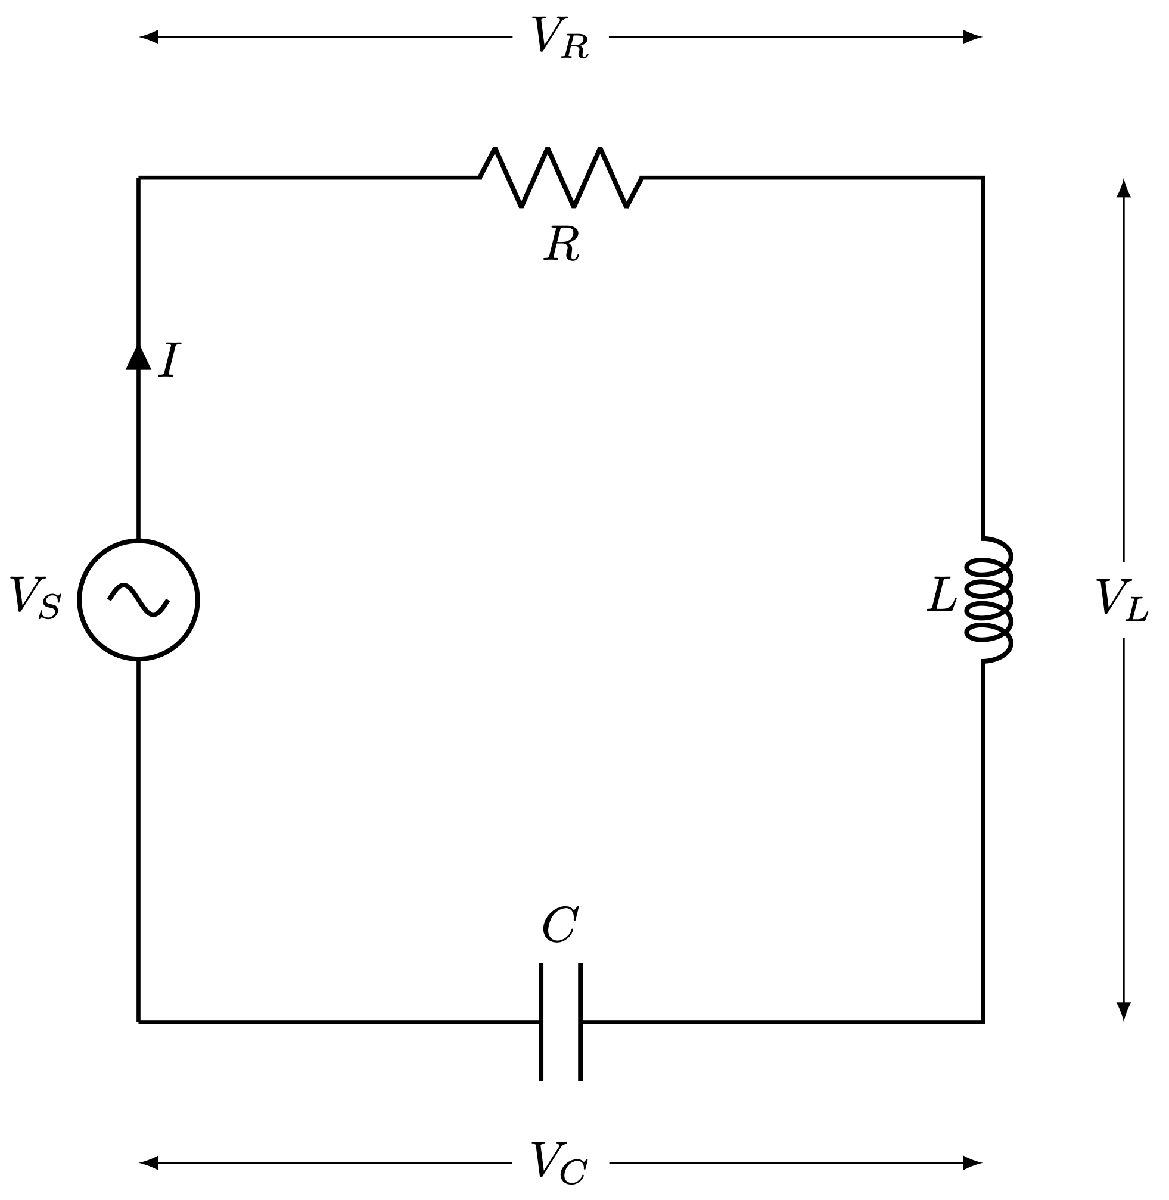$\;\Longleftrightarrow \;
\left\{ \begin{array}{rcl} 
L\,\displaystyle \frac{d\;}{d\,t}\,I(t) +R\,I(t) + \frac{1}{C}\,\int_0^{t} I(\tau)\,d \tau &=& V_S(t) \\ \\
I(0) &=& I_0
\end{array} \right. \quad I(t) = ?\,,\; t \ge 0$

[refer to the class material **Part 2**, **pp. 28-30**] $\left\{\begin{array}{l}
\dot{x}(t) = A\,x(t) + B\,u(t) \\
x(0) = x_0 \\
u(t)\,,\; t \ge 0
\end{array} \right. \quad x(t) = ?\,,\; t \ge 0$

-  Differential and  integro-differential equations in the time domain: they can be **difficult** **to** **solve**.

-  Apply the Laplace transform: transform to the s-domain. 

-  Differential and  integro-differential equations become **algebraic equations**: **easy to solve**!

-  Transform the s-domain solution back to the time domain.

### Causal Functions

- We are interested in functions in the time domain $f(t)$ defined for t ≥ 0, assuming they are null for all negative times, i.e $f(t) \equiv 0 \; \forall t<0$

- Time domain functions that have this property are called **causal** **functions**.

#### Example: The Heaviside Function

This is the first example of a causal function:


$$\mathbf{1}(t):= \left\{ \begin{array}{rcl} 0, &\;& \forall t <0 \\ 1, &\;& \forall t \ge 0 \end{array} \right. \qquad (\triangle)$$


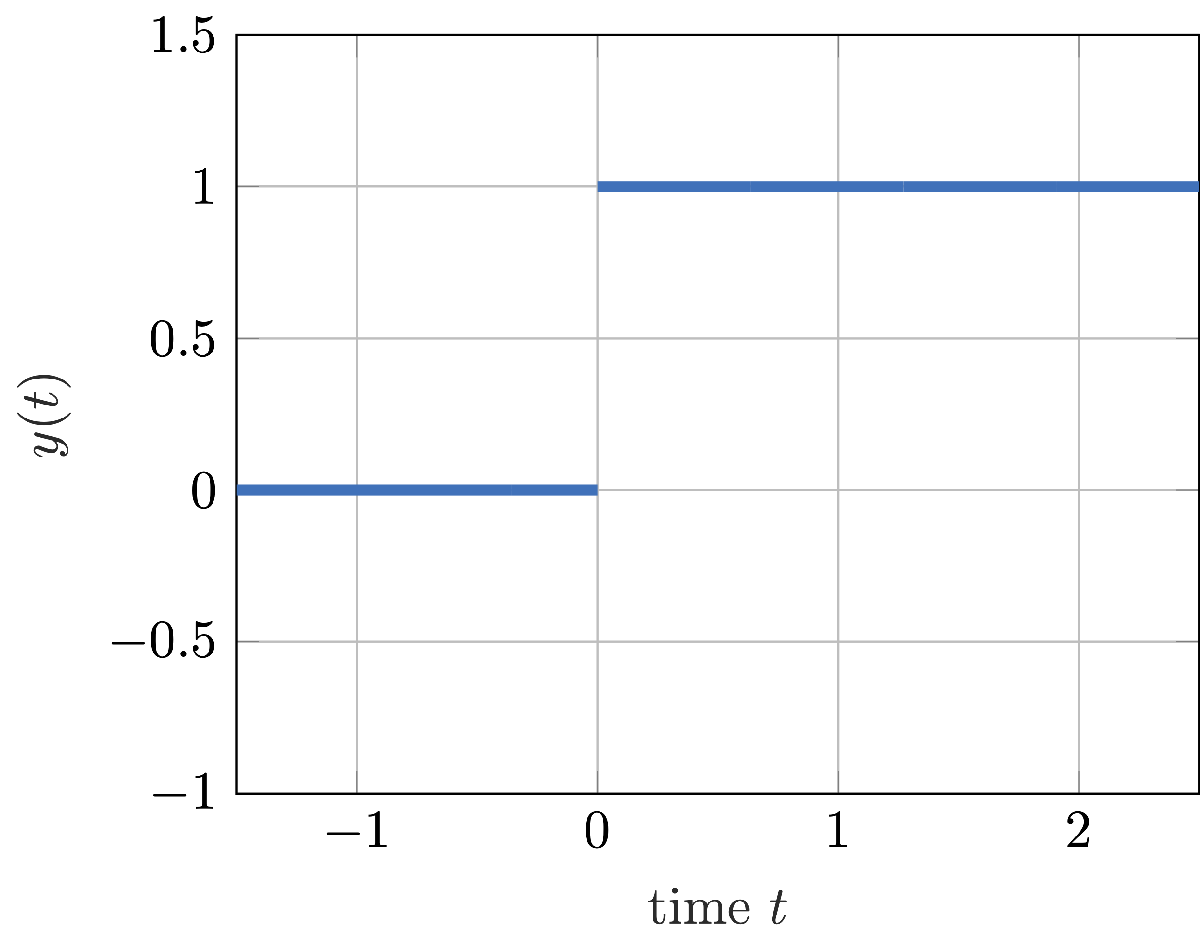

The Heaviside function is defined in the Symbolic Math Toolbox and it corresponds to the MATLAB function `heaviside`. 

**Pay** **attention**: by default, the definition of this function in the Symbolic Math Toolbox is different:

clear

sympref('default'); 
disp(heaviside(sym([-10, -1/10000, 0, +1/10000, 10])))

$$\left(\begin{array}{ccccc} 0 & 0 & \frac{1}{2} & 1 & 1 \end{array}\right)$$

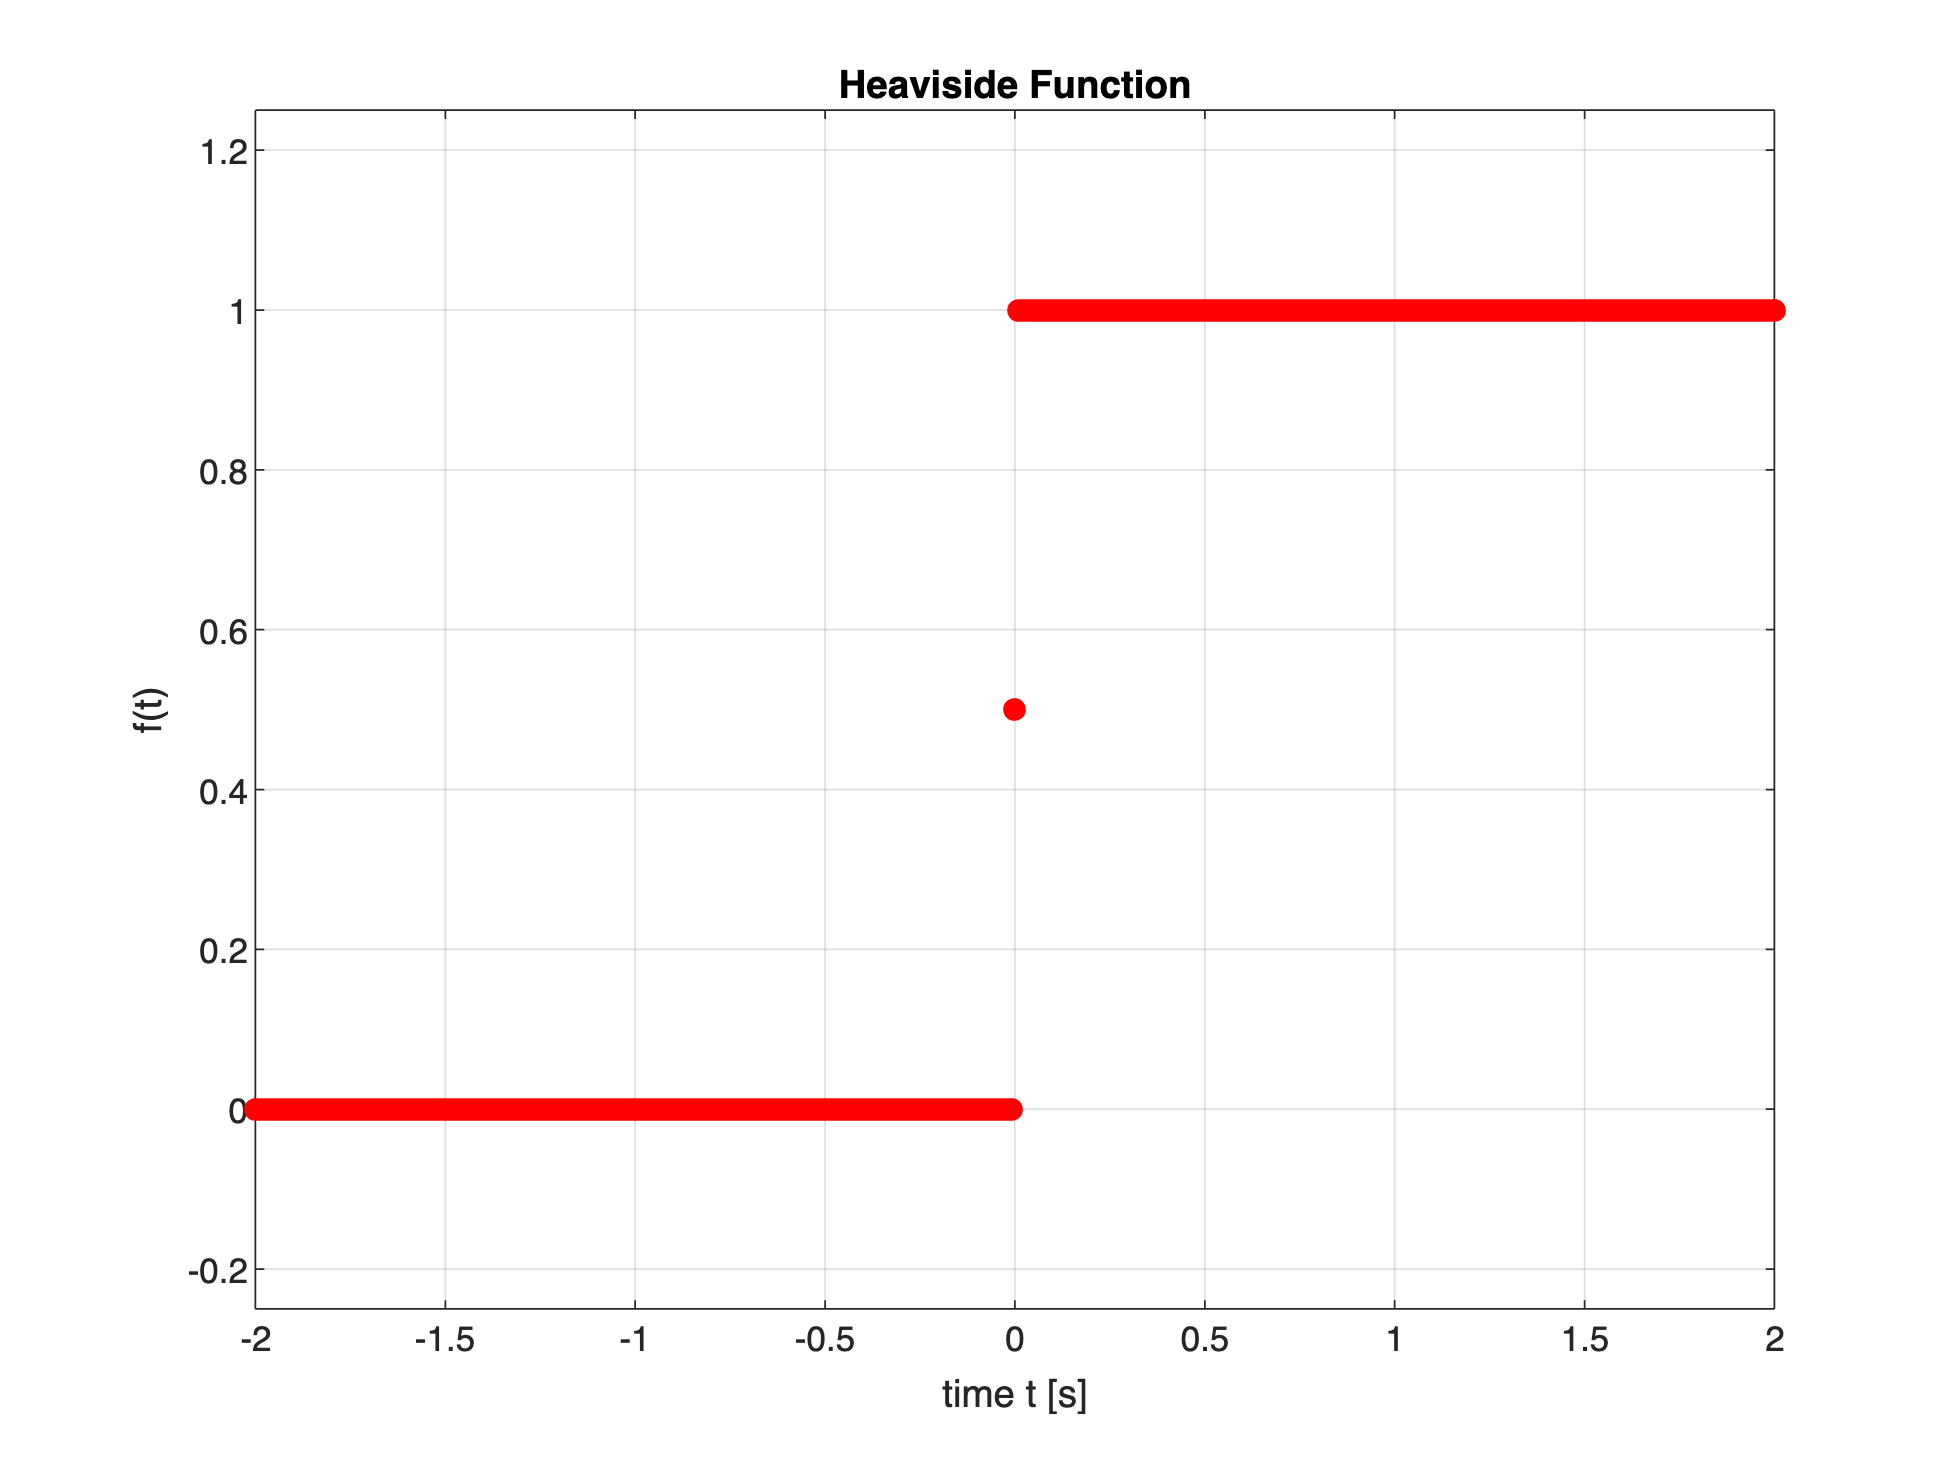

tVALs = (-2:1e-2:2); % refer to Part 3 of "Introduction to MATLAB"
plot(tVALs, heaviside(sym(tVALs)), 'LineStyle', 'none', 'Marker','o', 'MarkerSize', 6, ...
    'MarkerEdgeColor','r', 'MarkerFaceColor','r')
grid on; xlabel('time t [s]'); ylabel('f(t)');
title('Heaviside Function')
ylim([-0.25, 1.25])

 Note the function value at $t=0$ (recall the default configuration of the Symbolic Math Toolbox, analysed at the beginning  of the live script [*Introduction to MATLAB Part  4 - Symbolic Math Computations*](matlab:open('./Intro_MATLAB_034IN_FAC_p4.mlx')) ).

To adapt the Heaviside function, we have to modify the toolbox configuration preferences, as follows:

sympref('HeavisideAtOrigin', 1);  % forcing the setting for the Heaviside function 

disp(heaviside(sym([-10, -1/10000, 0, +1/10000, 10])))

$$\left(\begin{array}{ccccc} 0 & 0 & 1 & 1 & 1 \end{array}\right)$$

Now the behaviour of the Heaviside function is in accordance with the definition $(\triangle)$.

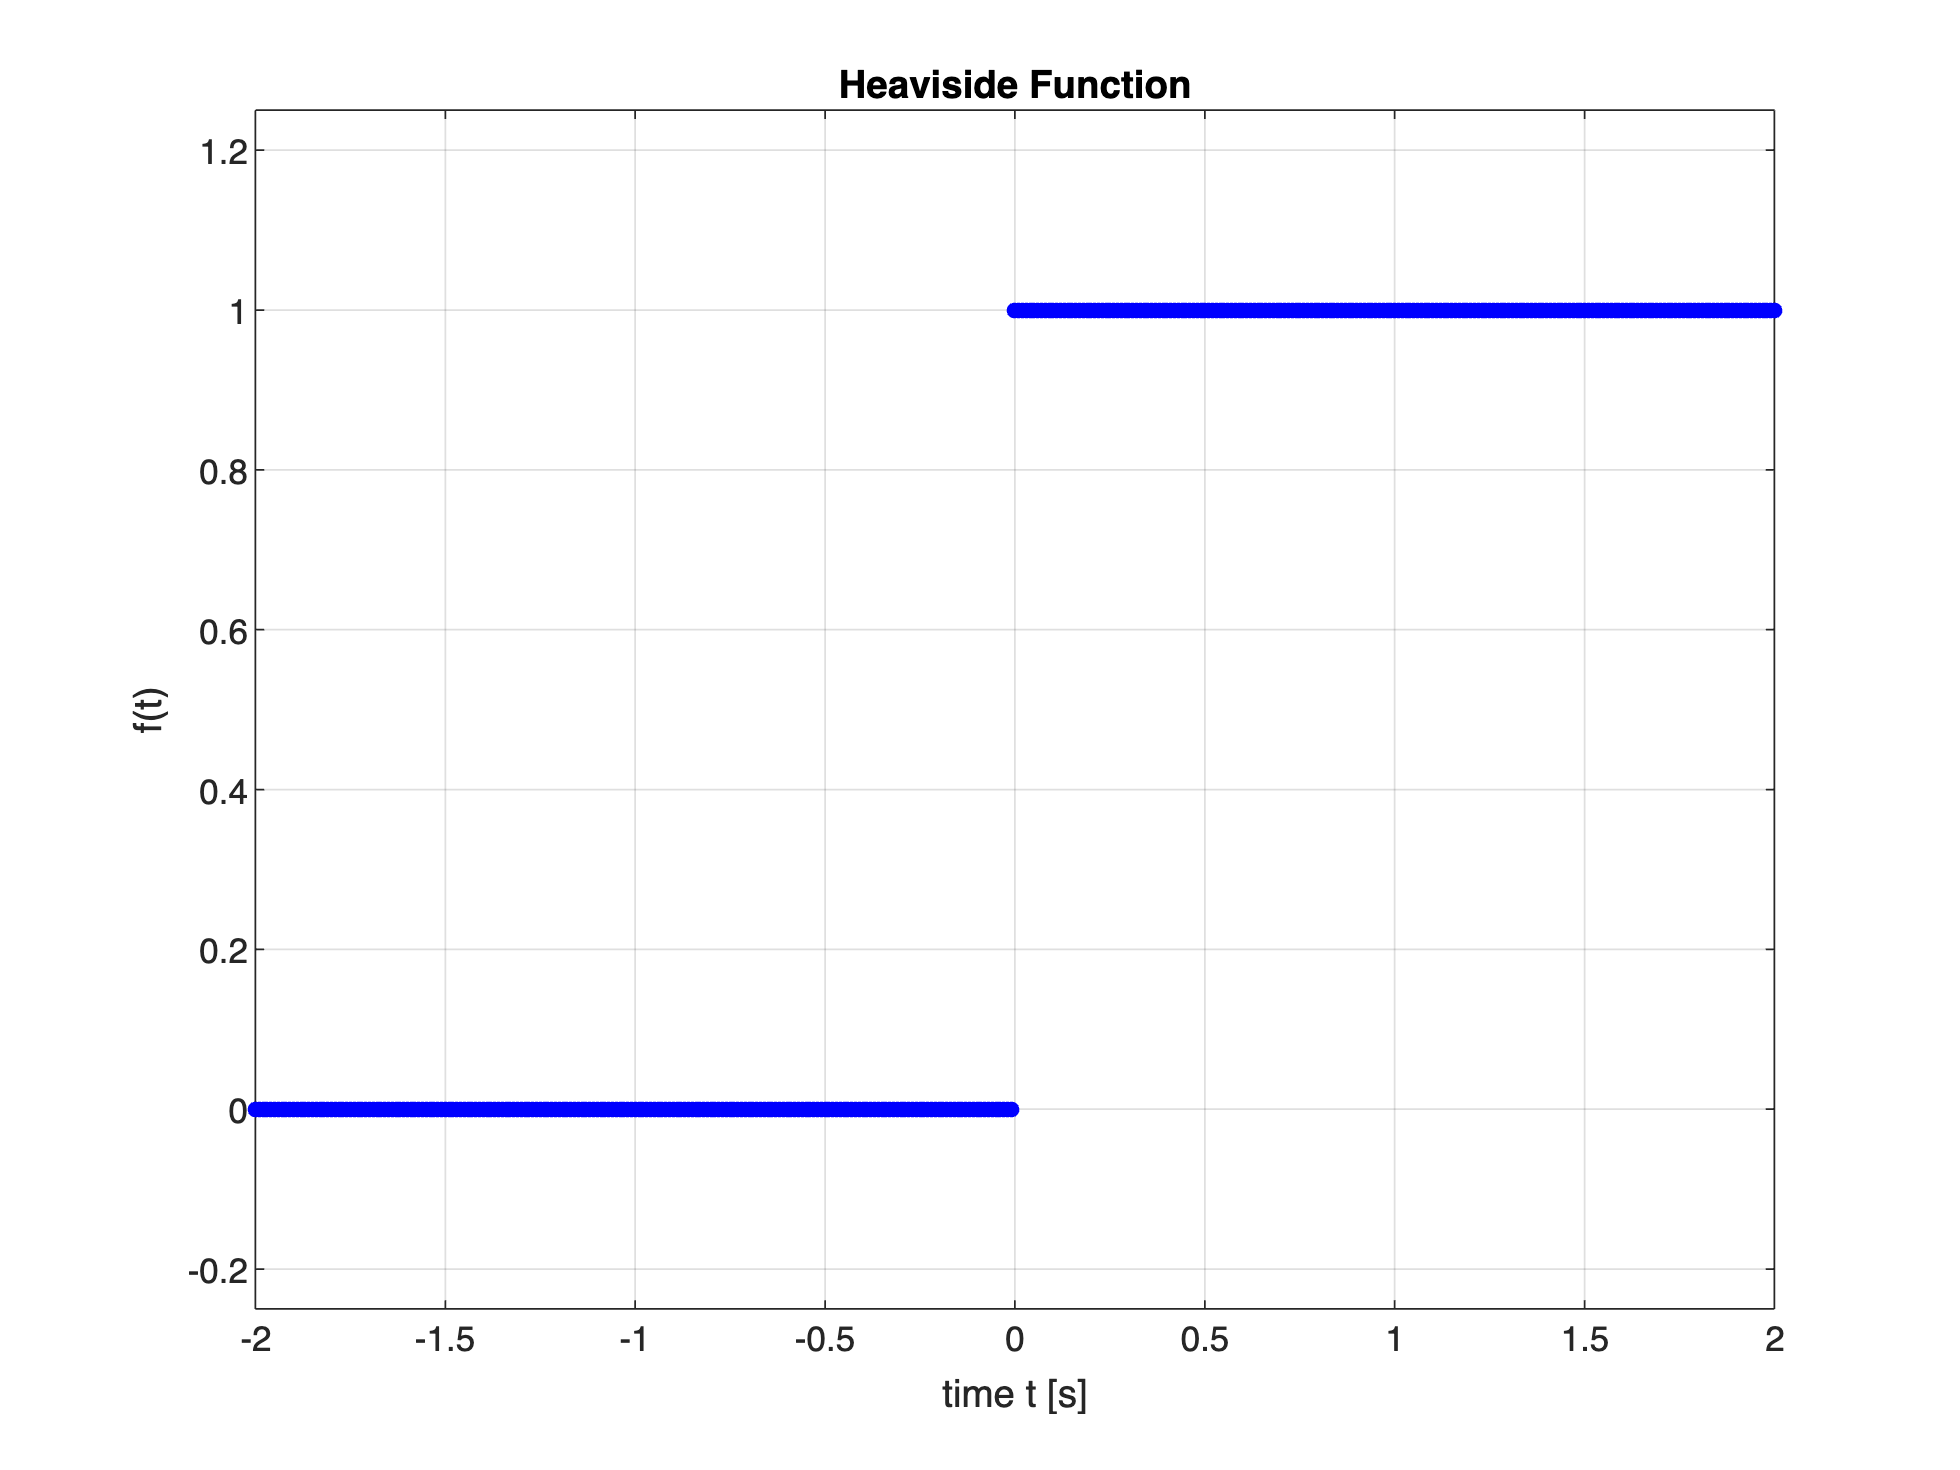

% tVALs = (-2:1e-2:2);
plot(tVALs, heaviside(sym(tVALs)), 'LineStyle', 'none', 'Marker','o', 'MarkerSize', 4, ...
    'MarkerEdgeColor','b', 'MarkerFaceColor','b')
grid on; xlabel('time t [s]'); ylabel('f(t)');
title('Heaviside Function')
ylim([-0.25, 1.25]);

#### Another Example

Usually we will use the Heaviside function $1(t)$ to emphasise that we are considering a causal function:


$$f(t) = \left[3\,\sin\left(4\,t+\frac{\pi}{3} \right) \right]\cdot 1(t) \quad \Longleftrightarrow \quad 
f(t) = \left\{ \begin{array}{lcl}
0\,, &\;& \forall t<0 \\
3\,\sin\left(4\,t+\frac{\pi}{3} \right) \,,&\;& \forall t \ge 0
\end{array} \right..$$


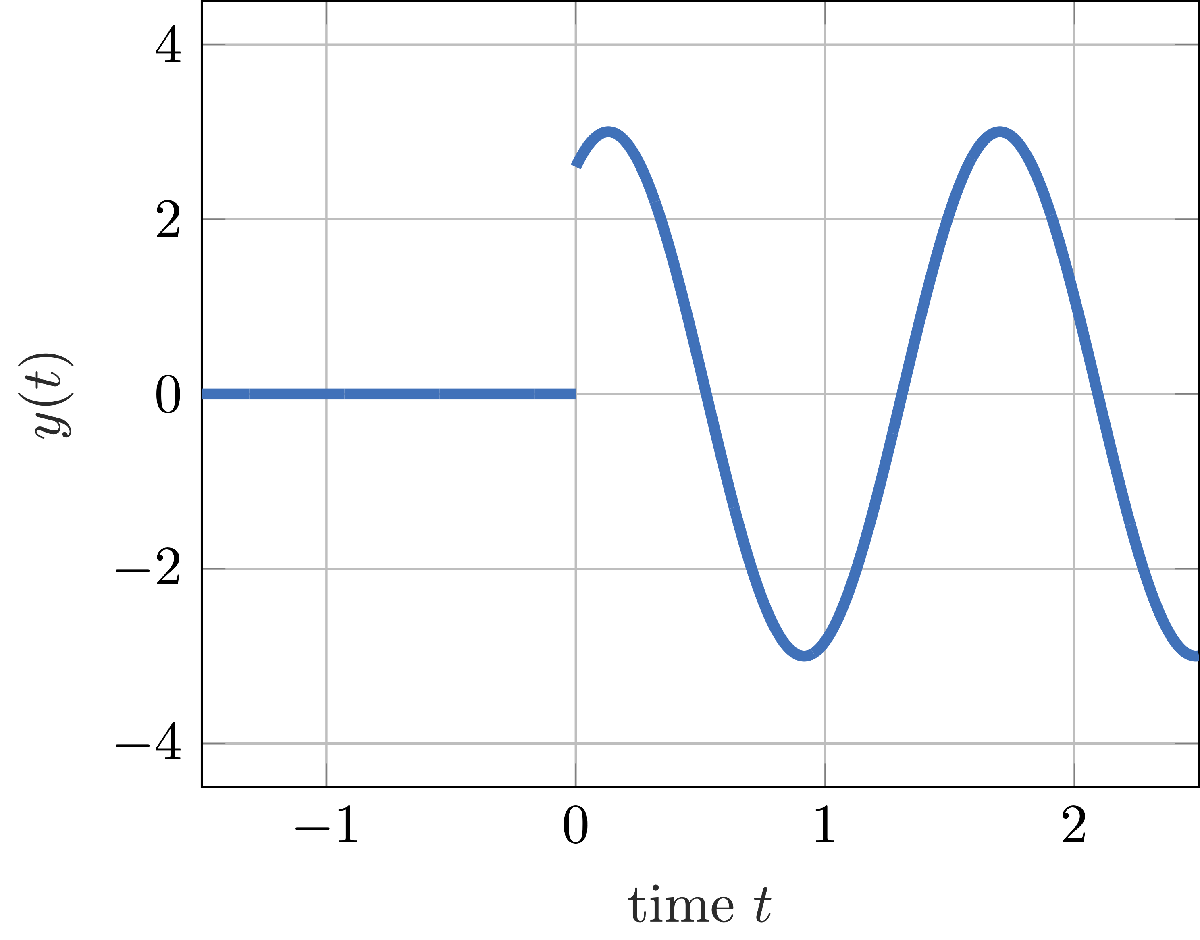

How do you do this in MATLAB?

syms t
f_causal(t) = 3*sin(4*t+pi/3)*heaviside(t)

$$f\_causal(t) = 3\,\sin\left(4\,t+\frac{\pi }{3}\right)\,\mathrm{heaviside}\left(t\right)$$

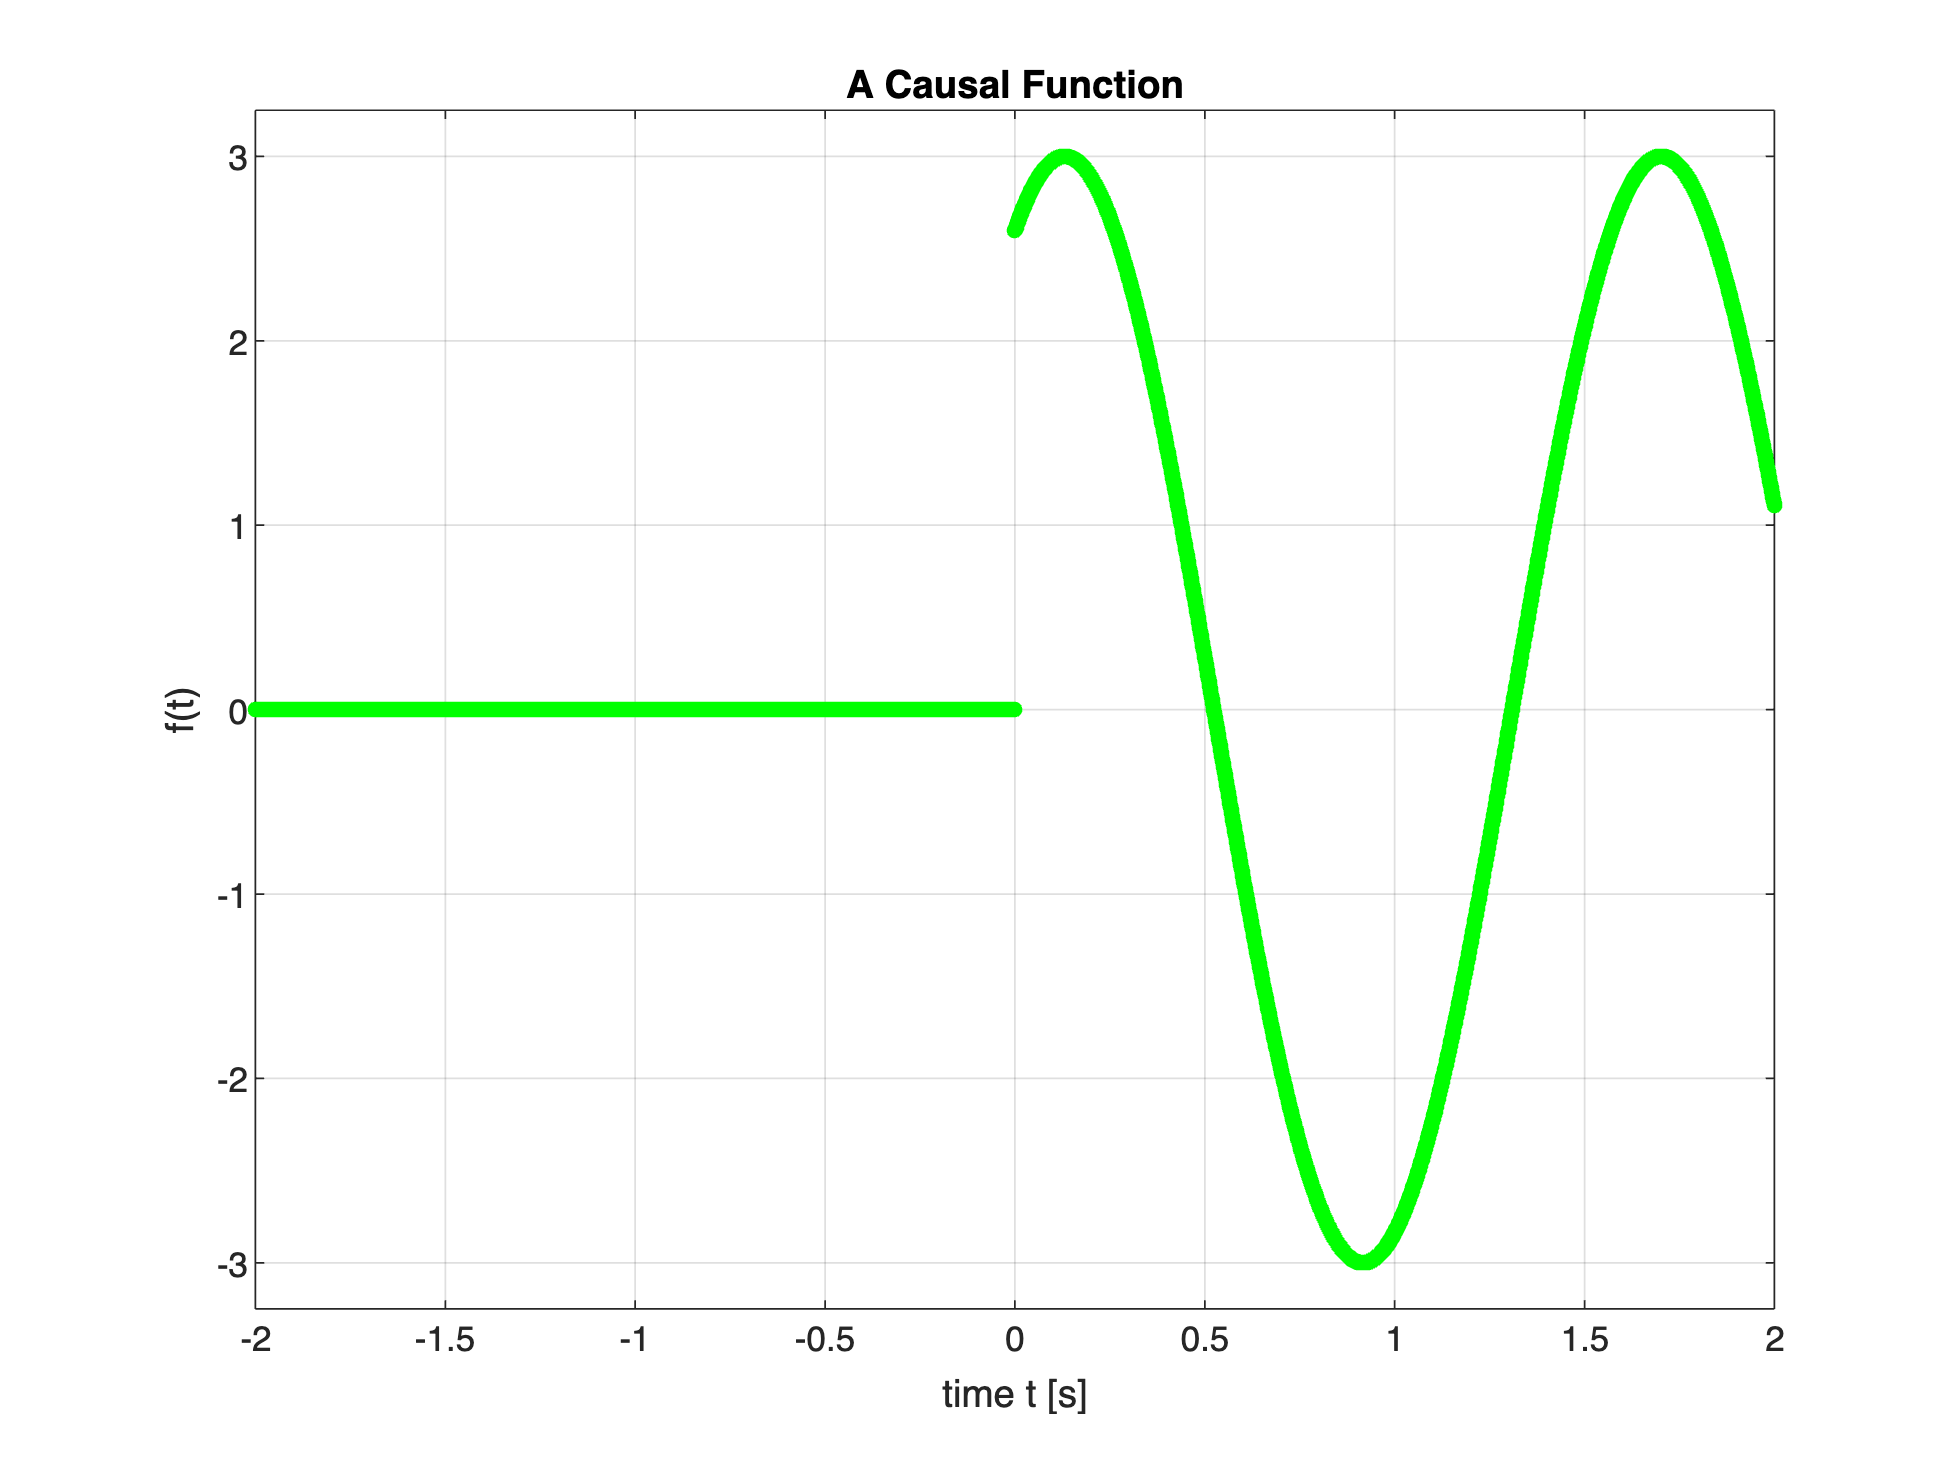

tVALs = (-2:1e-3:2);
plot(tVALs, f_causal(sym(tVALs)), 'LineStyle', 'none', 'Marker','o', 'MarkerSize', 4, ...
    'MarkerEdgeColor','g', 'MarkerFaceColor','g')
grid on; xlabel('time t [s]'); ylabel('f(t)');
title('A Causal Function')
ylim([-3.25, 3.25]);

### The Unilateral or One-Sided Laplace Transform

#### Definition

Given a causal function $f(t)$, the Laplace transform of $f(t)$ is the function $F(s) := \mathcal{L}\left(f\right)$ defined by


$$F(s) := \int_0^{+\infty} f(t)\,e^{-s\,t}\,d\,t$$


for those $s \in \mathbb{C}$ for which the integral makes sense.

- $F$ is a complex-valued function of complex numbers;

- $s$ is called the (*complex*) *frequency* variable, with units $\text{s}^{-1}$; $t$ is called the time variable (meas. units $\text{s}$);

- the lower limit of integration is $t=0$: the transform is called the **unilateral** or **one-sided Laplace transform**.

- **Commmon notation convention**: lower case letter denotes the time-domain function $f(t)$; capital letter denotes its Laplace transform $F(s) = \mathcal{L}\left(f(t) \right)$

#### Existance

 Which class or classes of functions possess a Laplace transform?

- **Fact 1**: $f(t)$ is continuous for $t=0$; if not,  $f(t)$ must contain **no impulses at  **$t=0$.

- **Fact 2**: any continuous, bounded, causal function $f(t)$ admits Laplace transform.

- **Fact 3**: any piecewise continuous, causal function $f(t)$ admits Laplace transform.

Piecewise continuous function $\Longleftrightarrow$ jump discontinuities and no vertical asymptotes.

**Examples:**

The function defined by


$$f(t) = \left\{ \begin{array}{rcl}
t^2\,, & \;& 0 \le t \le 1 \\
3-t\,, & \;& 1 < t \le 2 \\
t+1 \,, &\;& 2 < t 
\end{array}\right.$$


is piecewise continuous on $[0, +\infty )$.

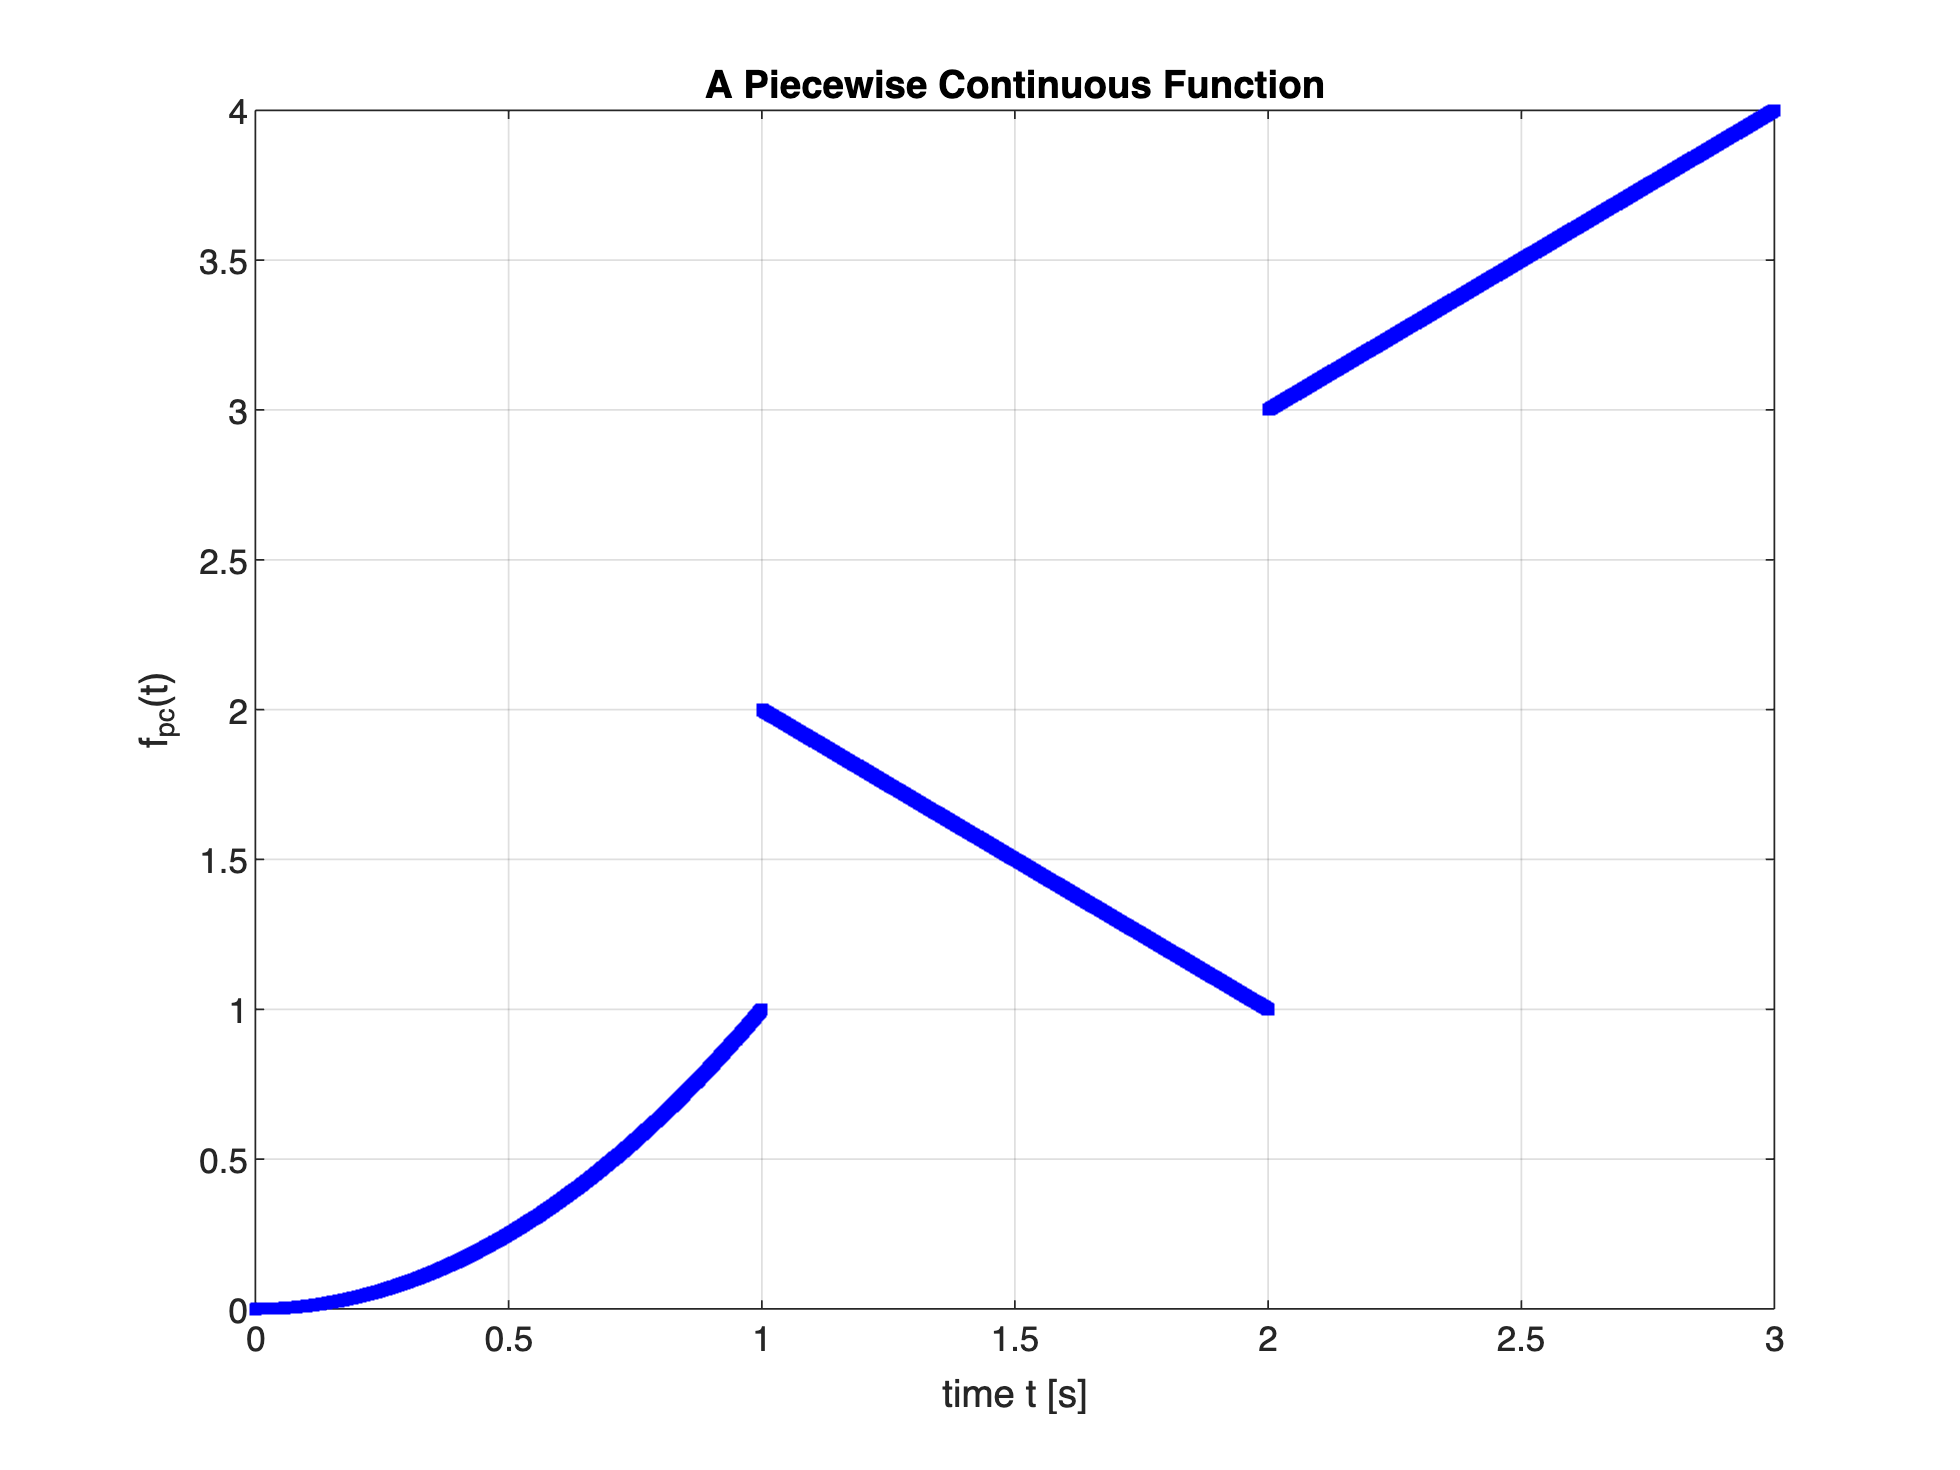

clear t tVALs
syms t

assume(t>0)
f_pc(t) = symfun(piecewise( (0<=t & t<=1), t^2, ...
                     (1<t & t<=2), 3-t, ...
                     2<t , t+1 ), t);

tVALs = (0:1e-3:3); % 3001 values in [0, 3]
plot(tVALs, f_pc(sym(tVALs)),  'LineStyle','none', 'Marker','square',...
      'MarkerSize',4, 'MarkerFaceColor','b', 'MarkerEdgeColor','b');
grid on;
xlabel('time t [s]'); ylabel('f_{pc}(t)');
title('A Piecewise Continuous Function')

The function defined by


$$f(t) = \left\{ \begin{array}{rcl}
\displaystyle \frac{1}{2-t}\,, & \;&0\le t \le 2 \\
t+1 \,, &\;& 2 < t 
\end{array}\right.$$


is **NOT** piecewise continuous on $[0, +\infty )$.

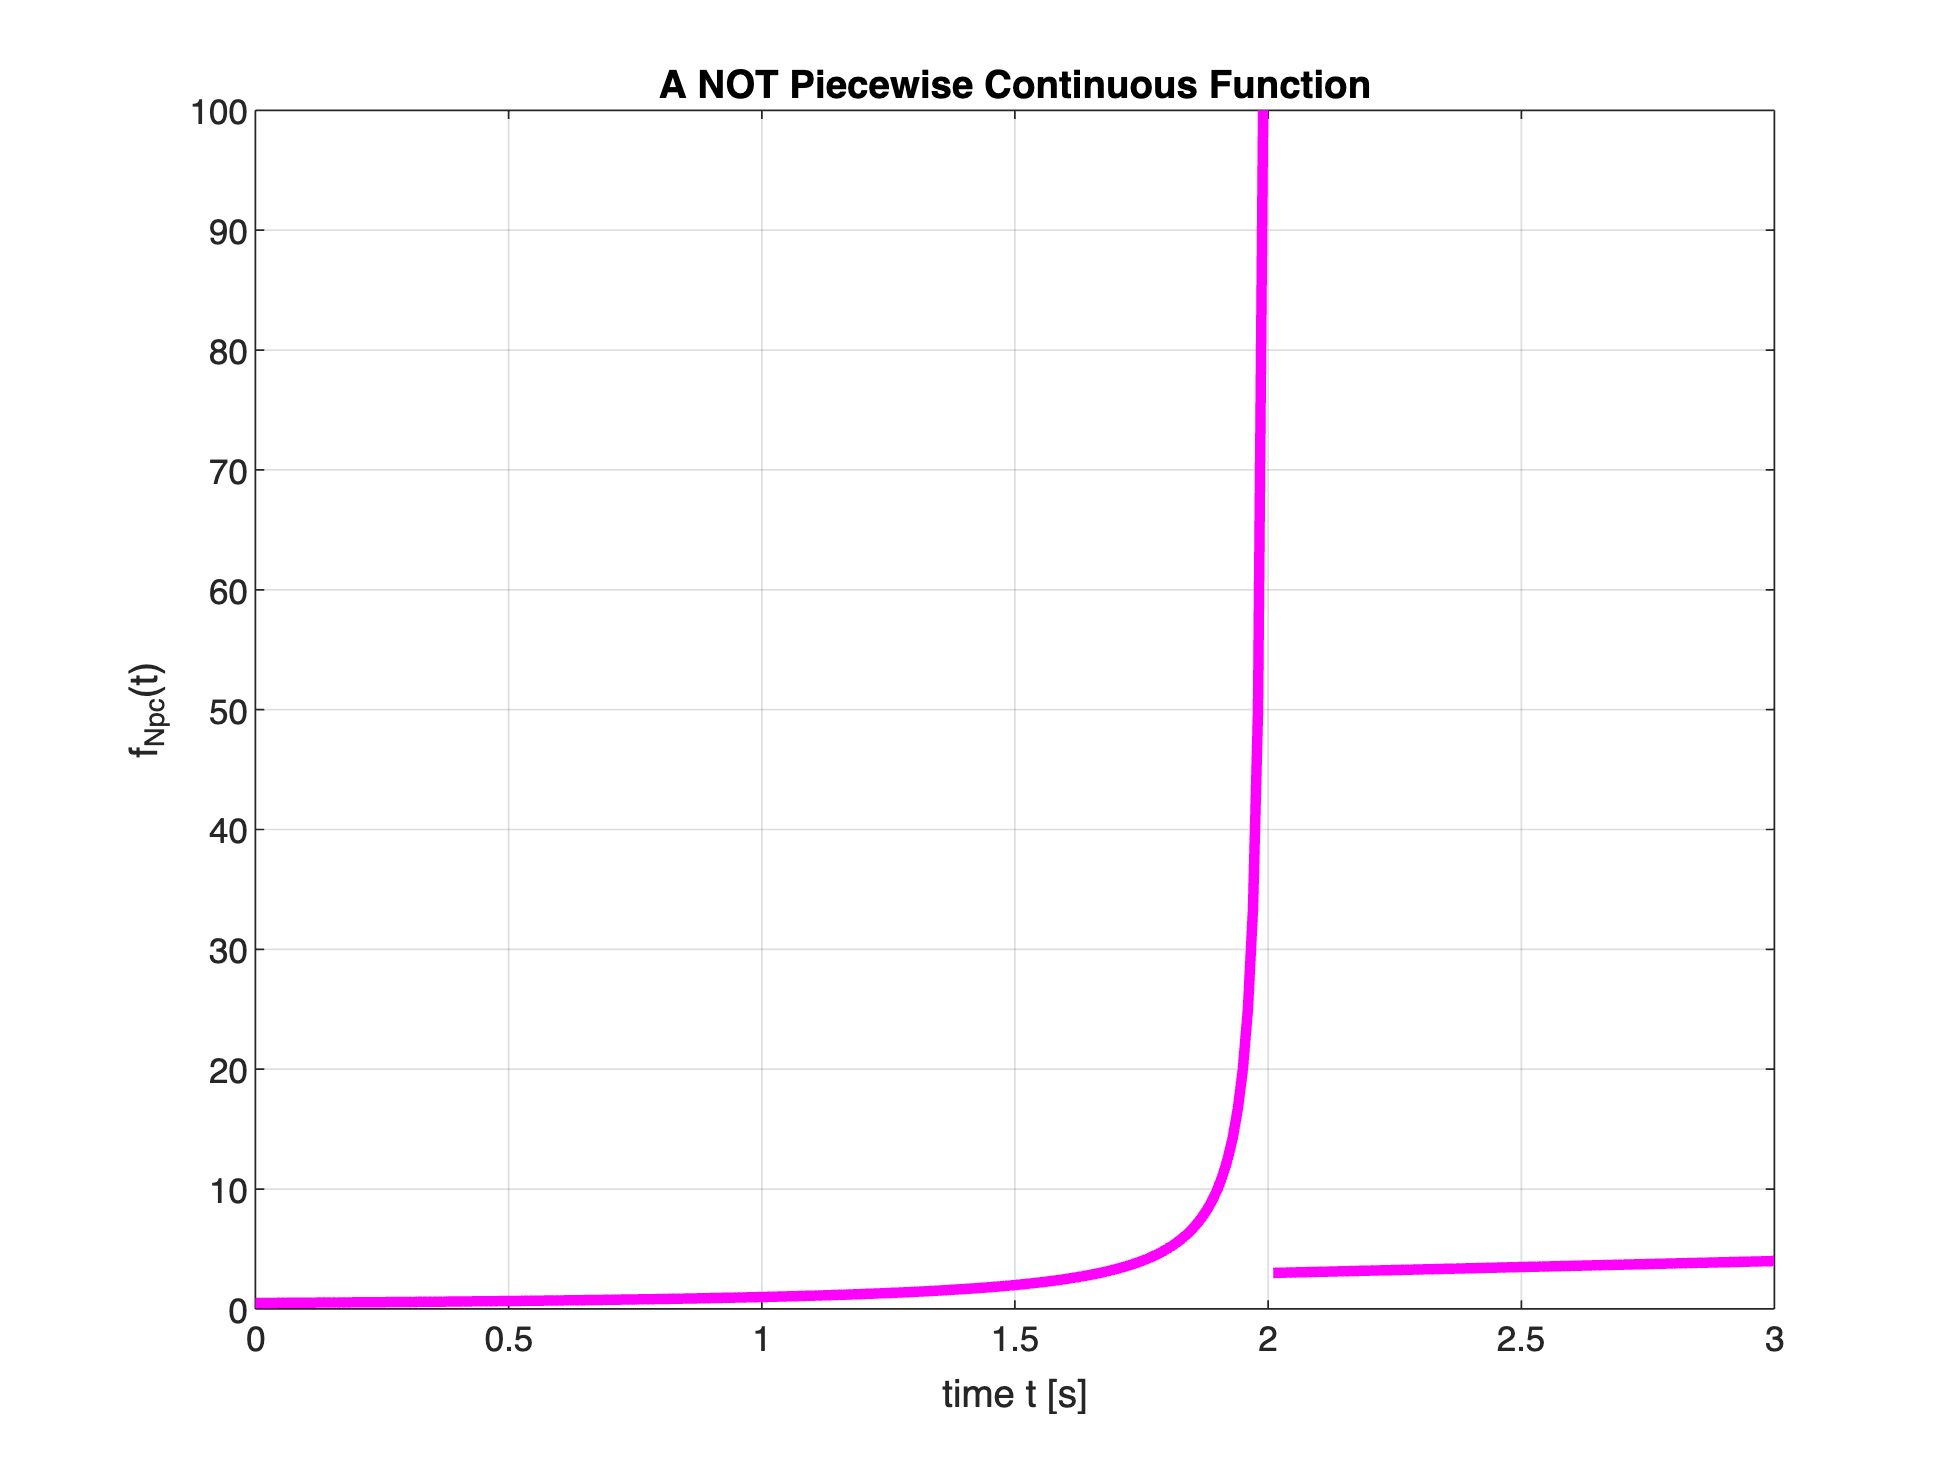

f_Npc(t) = symfun(piecewise( (0<=t & t<=2), 1/(2-t), ...
                               2<t , t+1 ), t);

tVALs = (0:1e-2:3); 
plot(tVALs, f_Npc(sym(tVALs)),  'LineStyle','-',...
      'Color', 'm', 'LineWidth', 3);
grid on;
xlabel('time t [s]'); ylabel('f_{Npc}(t)');
title('A NOT Piecewise Continuous Function')

For details on the commands symfun and piecewise, refer to

help piecewise

--- help for sym/piecewise ---

 sym/piecewise - Conditionally defined expression or function
    This MATLAB function returns the piecewise expression or function pw
    whose value is val1 when condition cond1 is true, is val2 when cond2 is
    true, and so on.

    Syntax
      pw = piecewise(cond1,val1,cond2,val2,...)
      pw = piecewise(cond1,val1,cond2,val2,...,otherwiseVal)

    Input Arguments
      cond - Condition
        symbolic condition | symbolic variable
      val - Value when condition is satisfied
        number | vector | matrix | multidimensional array |
        symbolic number | symbolic variable | symbolic vector |
        symbolic matrix | symbolic multidimensional array |
        symbolic func


help symfun

 symfun - Create symbolic functions
    This MATLAB function creates the symbolic function f.

    Syntax
      f(inputs) = formula
      f = symfun(formula,inputs)
      f = symfun(fM)

    Input Arguments
      formula - Function body
        symbolic expression | vector of symbolic expressions |
        matrix of symbolic expressions
      inputs - Input argument or arguments of function
        symbolic variable | array of symbolic variables
      fM - Symbolic matrix function to convert
        symbolic matrix function

    Output Arguments
      

#### Remark on Laplace Transform and Impulses

- Indeed, it is possible to cope with impulses, but you have to modify the definition of the Laplace transform slightly. 

- This topic is **out of the scope** of this course!

### Examples of Laplace Transforms

#### Exponential Function


$$f(t) = e^{t}\cdot 1(t) \;\Longleftrightarrow \; \mathcal{L}\left(f(t)\right) =\int_{0}^{\infty} e^{t}\,e^{-st} \, dt =  \displaystyle \frac{1}{s-1}  = F(s)$$


clear variables

syms t s

ft   = exp(t)*heaviside(t);

Fs = laplace(ft, t, s)

$$Fs = \frac{1}{s-1}$$

#### Unit Step Function - the Heaviside Function


$$h(t) =  1(t) \;\Longleftrightarrow \; \mathcal{L}\left(h(t)\right) =\int_{0}^{\infty} 1(t)\,e^{-st} \, dt =  \displaystyle \frac{1}{s}  = H(s)$$


clear variables

syms t s

ht   = heaviside(t);

Hs = laplace(ht, t, s)

$$Hs = \frac{1}{s}$$

### Important Remark: On Using the Heaviside Function Notation For Causal Functions

As pointed out in the [Laplace transform documentation](https://it.mathworks.com/help/symbolic/sym.laplace.html)

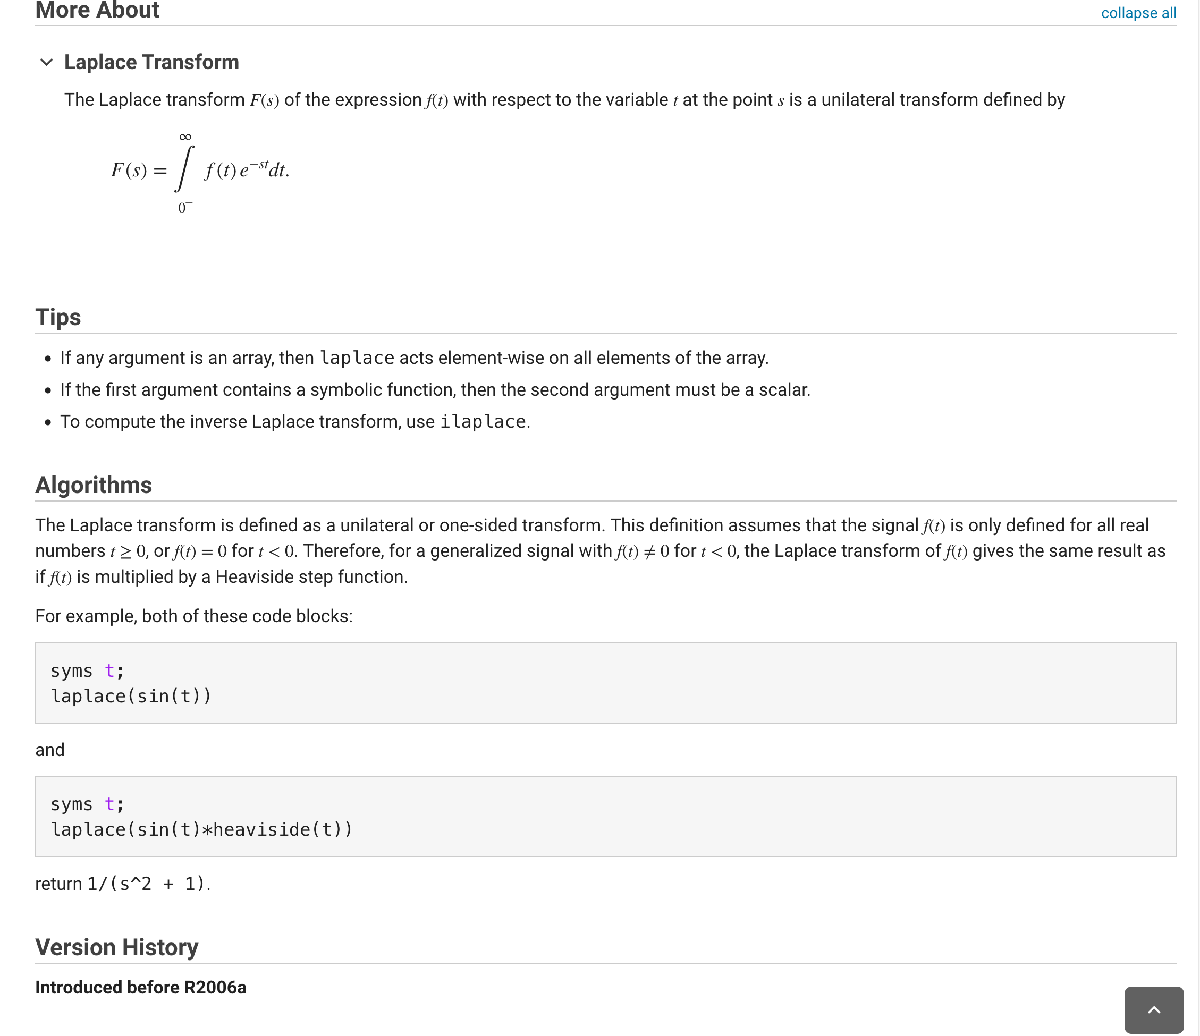

It means that 

- You can avoid inserting the Heaviside function explicitly to mark a function as causal **unless** you are dealing with delayed causal functions.

clear variables

syms t s

ft1(t)   = exp(t)*heaviside(t)

$$ft1(t) = {\mathrm{e}}^{t}\,\mathrm{heaviside}\left(t\right)$$

ft2(t)   = exp(t)

$$ft2(t) = {\mathrm{e}}^{t}$$


Fs1 = laplace(ft1, t, s)

$$Fs1 = \frac{1}{s-1}$$

Fs2 = laplace(ft2, t, s)

$$Fs2 = \frac{1}{s-1}$$

### Laplace Transforms Properties

#### Linearity

-  The Laplace transform is linear.

- If $f(t)$ and $g(t)$ are any causal functions, for which the Laplace transform exists, and $a$ is any scalar, we have

clear variables

syms t s 
syms f(t) g(t)
syms F(s) G(s)
syms a


omogeneityL = laplace(a*f(t))

$$omogeneityL = a\,\mathrm{laplace}\left(f\left(t\right),t,s\right)$$

omogeneityL = subs(omogeneityL, laplace(f(t)), F(s))

$$omogeneityL = a\,F\left(s\right)$$

superpositionl = laplace(f(t)+g(t), t, s);
superpositionl = subs(superpositionl, [laplace(f(t)), laplace(g(t))], [F(s), G(s)])

$$superpositionl = F\left(s\right)+G\left(s\right)$$

An example:

clear variables

syms t s
f(t) = 1*heaviside(t);
g(t) = exp(t);

F(s) = laplace(f(t), t, s);
G(s) = laplace(g(t), t, s);
disp([F, G])

$$\left(\begin{array}{cc} \frac{1}{s} & \frac{1}{s-1} \end{array}\right)$$

L(s) = laplace(3*f(t)+2*g(t), t, s)

$$L(s) = \frac{2}{s-1}+\frac{3}{s}$$

L(s) = collect(L, s)

$$L(s) = \frac{5\,s-3}{s^{2}-s}$$

L(s) = simplify(L)

$$L(s) = \frac{5\,s-3}{s\,\left(s-1\right)}$$

For details about the commands `subs`, `collect`, and `simplify`:

help sym/subs

 subs - Symbolic substitution
    This MATLAB function returns a copy of s, replacing all occurrences of
    old with new, and then evaluates s.

    Substitute Symbolic Scalar Variables and Functions
      snew = subs(s,old,new)
      snew = subs(s,new)
      snew = subs(s)

    Substitute Symbolic Matrix Variables and Functions
      sMnew = subs(sM,oldM,newM)
      sMnew = subs(sM,newM)
      sMnew = subs(sM)

    Input Arguments
      s - Symbolic input
        symbolic scalar variable | symbolic expression | symbolic equation |
        symbolic function | symbolic array | symbolic matrix | structure
      old - Scalar variable to substitute
        symbolic scalar variable | 

help sym/collect

 sym/collect - Collect coefficients of identical powers
    This MATLAB function collects the coefficients of identical powers of
    the default variable in the symbolic input P.

    Syntax
      C = collect(P)
      C = collect(P,expr)

    Input Arguments
      P - Input expression
        symbolic expression | symbolic function | symbolic vector |
        symbolic matrix
      expr - Expression in terms of which you collect coefficients
        symbolic number | symbolic variable | symbolic expression |
        symbolic function | symbolic vector | string array |
        character vector | cell array of character vectors

    Examples
      


help sym/simplify

 sym/simplify - Algebraic simplification
    This MATLAB function performs algebraic simplification of expr.

    Syntax
      S = simplify(expr)
      S = simplify(expr,Name,Value)

    Input Arguments
      expr - Input expression
        symbolic expression | symbolic function | symbolic vector |
        symbolic matrix

    Name-Value Arguments
      All - Option to return equivalent results
        false (default) | true
      Criterion - Simplification criterion
        'default' (default) | 'preferReal'
      I

#### Transform of a Derivative

If the causal function $f(t)$ is continuous at $t=0$, then


$$\mathcal{L} \left( \dot{f}(t) \right) = s\,F(s)-f(0)$$


clear variables

syms t s
syms f(t) dot_f(t)
syms F(s)

dot_f(t) = diff(f(t), 1); % the 1st derivative
Dot_F(s) = laplace(dot_f, t, s)

$$Dot\_F(s) = s\,\mathrm{laplace}\left(f\left(t\right),t,s\right)-f\left(0\right)$$

Dot_F(s) = subs(Dot_F(s), laplace(f(t), t, s), F(s))

$$Dot\_F(s) = s\,F\left(s\right)-f\left(0\right)$$

An example:


$$f(t) = 2\,\left(e^{t}-1) \cdot 1(t) \; \Longrightarrow \; \dot{f}(t) = 2e^{t} \,,\quad t \ge 0$$


clear variables

syms t s
syms f(t) dot_f(t)
syms F(s) DotF(s)

f(t) = 2*(exp(t)-1); % causal symbolic function of time t


Let's verify the continuity of $f(t)$ at $t=0$:

f0left = limit(f, t, 0, 'left')

$$f0left = 0$$

f0right = limit(f, t, 0, 'right')

$$f0right = 0$$

f(0)                 % the value of f(t) when t=0

$$ans = 0$$

F(s) = laplace(f, t, s) % Laplace transform of f(t)

$$F(s) = \frac{2}{s-1}-\frac{2}{s}$$

dot_f(t) = diff(f,t,1) % the 1st derivative of f(t)

$$dot\_f(t) = 2\,{\mathrm{e}}^{t}$$

DotF(s) = laplace(dot_f(t), t, s) % the Laplace transform of dot_f

$$DotF(s) = \frac{2}{s-1}$$

% the Laplace transform of the derivative of f(t)
DotF_ALT(s) = laplace(diff(f, t, 1), t, s) 

$$DotF\_ALT(s) = \frac{2}{s-1}$$

% the Laplace transform, applying the derivative property "by hand"
DotF_ALT2(s) = collect( (s*F(s)-f(0)), s)

$$DotF\_ALT2(s) = \frac{2}{s-1}$$

For details about the command diff:

help diff

 diff - Differences and approximate derivatives
    This MATLAB function calculates differences between adjacent elements of
    X.

    Syntax
      Y = diff(X)
      Y = diff(X,n)
      Y = diff(X,n,dim)

    Input Arguments
      X - Input array
        vector | matrix | multidimensional array | table | timetable
      n - Difference order
        positive integer scalar | []
      dim - Dimension to operate along
        positive integer scalar

    Output Arguments
      Y - Difference array
        scalar | vec

#### Higher-Order Derivatives

- Applying derivative formula twice yields


$$\begin{array}{rcl}
\mathcal{L} \left(\ddot{f} \right) &=& s\,\mathcal{L} \left(\dot{f} \right) - \dot{f}(0) \\
&=& s\,\big( s\,F(s) - f(0) \big) - \dot{f}(0) \\
&= &s^2 \,F(s) -s\, f(0) - \dot{f}(0)
\end{array}$$


-  A similar formula holds for the $k$-th order derivative


$$\mathcal{L} \left(f^{(k)} \right) = s^{k} \,F(s) -\sum_{n=0}^{k-1} \, s^{k-n-1}\,f^{(n)}(0)$$


**Examples:**

clear variables

syms t s
syms f(t) dot_f(t) ddot_f(t)

dot_f(t) = diff(f, 1); % the 1st derivative
ddot_f(t) = diff(f, 2); % the 2nd derivative
Dot_F(s) = laplace(dot_f, t, s)

$$Dot\_F(s) = s\,\mathrm{laplace}\left(f\left(t\right),t,s\right)-f\left(0\right)$$

DDot_F(s) = laplace(ddot_f, t, s)

$$DDot\_F(s) = s^{2}\,\mathrm{laplace}\left(f\left(t\right),t,s\right)-\left({\left(\frac{\partial }{\partial t}f\left(t\right)\right)|}_{t=0}\right)-s\,f\left(0\right)$$

Given the causal function 


$$f(t) = 2\,\left(e^{3\,t}-1) \cdot 1(t) \; \Longrightarrow \; \dot{f}(t) = 6e^{3\,t} \,,\; t \ge 0  \; \Longrightarrow \; \ddot{f}(t) = 18e^{3\,t} \,,\; t \ge 0 $$


clear variables

syms t s
syms f(t) dot_f(t) ddot_f(t)

f(t) = 2*(exp(3*t)-1)

$$f(t) = 2\,{\mathrm{e}}^{3\,t}-2$$

dot_f(t) = diff(f, 1) % the 1st derivative

$$dot\_f(t) = 6\,{\mathrm{e}}^{3\,t}$$

ddot_f(t) = diff(f, 2) % the 2nd derivative

$$ddot\_f(t) = 18\,{\mathrm{e}}^{3\,t}$$

DDot_F(s) = laplace(ddot_f, t, s)

$$DDot\_F(s) = \frac{18}{s-3}$$


DDotF_ALT(s) = s^2*laplace(f, t, s)-s*f(0)-dot_f(0)

$$DDotF\_ALT(s) = s^{2}\,\left(\frac{2}{s-3}-\frac{2}{s}\right)-6$$

collect(DDot_F, s)

$$ans(s) = \frac{18}{s-3}$$

#### Transform of an Integral

Let $g(t)$ be the running integral of a causal function $f(t)$: 


$$\quad g(t) = \displaystyle \int_0^{t} f(\tau)\,d \tau \;\Longleftrightarrow \; G(s) = \mathcal{L}\left(g(t) \right) = \frac{1}{s}\,F(s)$$


where $F(s) = \mathcal{L}\left(f(t) \right)$.

An example:

clear variables

syms t s tau

assume(tau >=0)
assumptions

$$ans = 0\leq \tau$$


syms f(t) g(t)

f(t) = heaviside(t);
F(s) = laplace(f, t, s)

$$F(s) = \frac{1}{s}$$

assumeAlso(t>0)
g(t) = int(f(tau), tau, 0, t)

$$g(t) = t$$

G(s) = simplify(laplace(g(t), t, s))

$$G(s) = \frac{1}{s^{2}}$$

#### Multiplication by t

Let $f(t)$ be a causal function and define  $g(t) = t \cdot f(t)$. Then  $G(s) = \mathcal{L}\left(g(t) \right) = - \frac{d}{d\,s} F(s)$, where $F(s) = \mathcal{L}\left(f(t) \right)$

Examples:


$$f(t) = e^{t}\cdot 1(t)\,,\; g(t) = t\,e^{t}\cdot 1(t) \quad \Longleftrightarrow \quad
\mathcal{L}\left(g(t)\right) = -\frac{d}{d\,s} \left(\frac{1}{s-1}\right) = \frac{1}{(s-1)^2}$$


clear variables

syms t s 
f(t) = exp(t);
g(t) = t*exp(t);

F(s) = laplace(f, t, s);
G(s) = laplace(g, t, s)

$$G(s) = \frac{1}{{\left(s-1\right)}^{2}}$$


G_ALT = -diff(F, s, 1)

$$G\_ALT(s) = \frac{1}{{\left(s-1\right)}^{2}}$$


$$f(t) = t\,e^{t}\cdot 1(t)\,,\; g(t) = t^2\,e^{t}\cdot 1(t) \quad \Longleftrightarrow \quad
\mathcal{L}\left(g(t)\right) = -\frac{d}{d\,s}\left(\frac{1}{(s-1)^2}\right) = \frac{2}{(s-1)^3}$$


clear variables

syms t s 
f(t) = exp(t);
F(s) = laplace(f, t, s);
f1(t) = t*exp(t);
g1(t) = t^2*exp(t);
F1(s) = laplace(f1, t, s);
G1(s) = laplace(g1, t, s)

$$G1(s) = \frac{2}{{\left(s-1\right)}^{3}}$$


G1_ALT = -diff(F1, s, 1)

$$G1\_ALT(s) = \frac{2}{{\left(s-1\right)}^{3}}$$


G1_ALT_ALT = -diff(-diff(F, s, 1), s, 1)

$$G1\_ALT\_ALT(s) = \frac{2}{{\left(s-1\right)}^{3}}$$

#### Exponential Scaling (Frequency Shifting)

Let $f(t)$ be a causal function, with Laplace transform $F(s)$, and let g(t) be defined as ( $a$ is a scalar value)


$$g(t) = e^{a\,t} \cdot f(t) \quad \Longleftrightarrow \quad \mathcal{L}\left(g(t)\right) = G(s) = F(s-a)$$


An example:

- given $\mathcal{L}\left[ \left(\cos(\omega t)\right)\cdot 1(t) \right] = \frac{s}{s^2+\omega^2}$ then


$$
\mathcal{L}\left[ \left( e^{-t}\cos( t)\right)\cdot 1(t) \right] = \frac{(s+1)}{(s+1)^2+1} 
= \frac{s+1}{s^2+2s+2}
$$


clear variables

syms t s omega

f(t) = cos(omega*t)

$$f(t) = \cos\left(\omega \,t\right)$$


g(t) = exp(-t)*f(t)

$$g(t) = {\mathrm{e}}^{-t}\,\cos\left(\omega \,t\right)$$


F(s) = laplace(f, t, s)

$$F(s) = \frac{s}{\omega^{2}+s^{2}}$$


G(s) = laplace(g, t, s)

$$G(s) = \frac{s+1}{{\left(s+1\right)}^{2}+\omega^{2}}$$

subs(F(s), omega, 1)

$$ans = \frac{s}{s^{2}+1}$$

collect(subs(G(s), omega, 1))

$$ans = \frac{s+1}{s^{2}+2\,s+2}$$

#### Time Shifting (Time Delay)

- Let $f(t)$ be a causal function, with Laplace transform $F(s)$.

- Define the causal function $g(t)$ as 


$$g(t) = f\left(t-T \right) \cdot 1\left(t-T\right)\;, \qquad T>0$$


- Then:


$$\mathcal{L} \left(g(t) \right) = G(s) = e^{-s\,T}\,F(s)$$


An example:


$$f(t) = 1(t-a) -1(t-b) \quad \Longleftrightarrow \quad F(s) = \mathcal{L}\left(1(t-a)\right) - \mathcal{L}\left(1(t-b)\right) = \frac{e^{-a\,s}-e^{-b\,s}}{s}
$$


clear variables
syms t s 

a = sym(2); % the first delay term
b = sym(5); % the second delay term

f(t) = heaviside(t-a)-heaviside(t-b)

$$f(t) = \mathrm{heaviside}\left(t-2\right)-\mathrm{heaviside}\left(t-5\right)$$

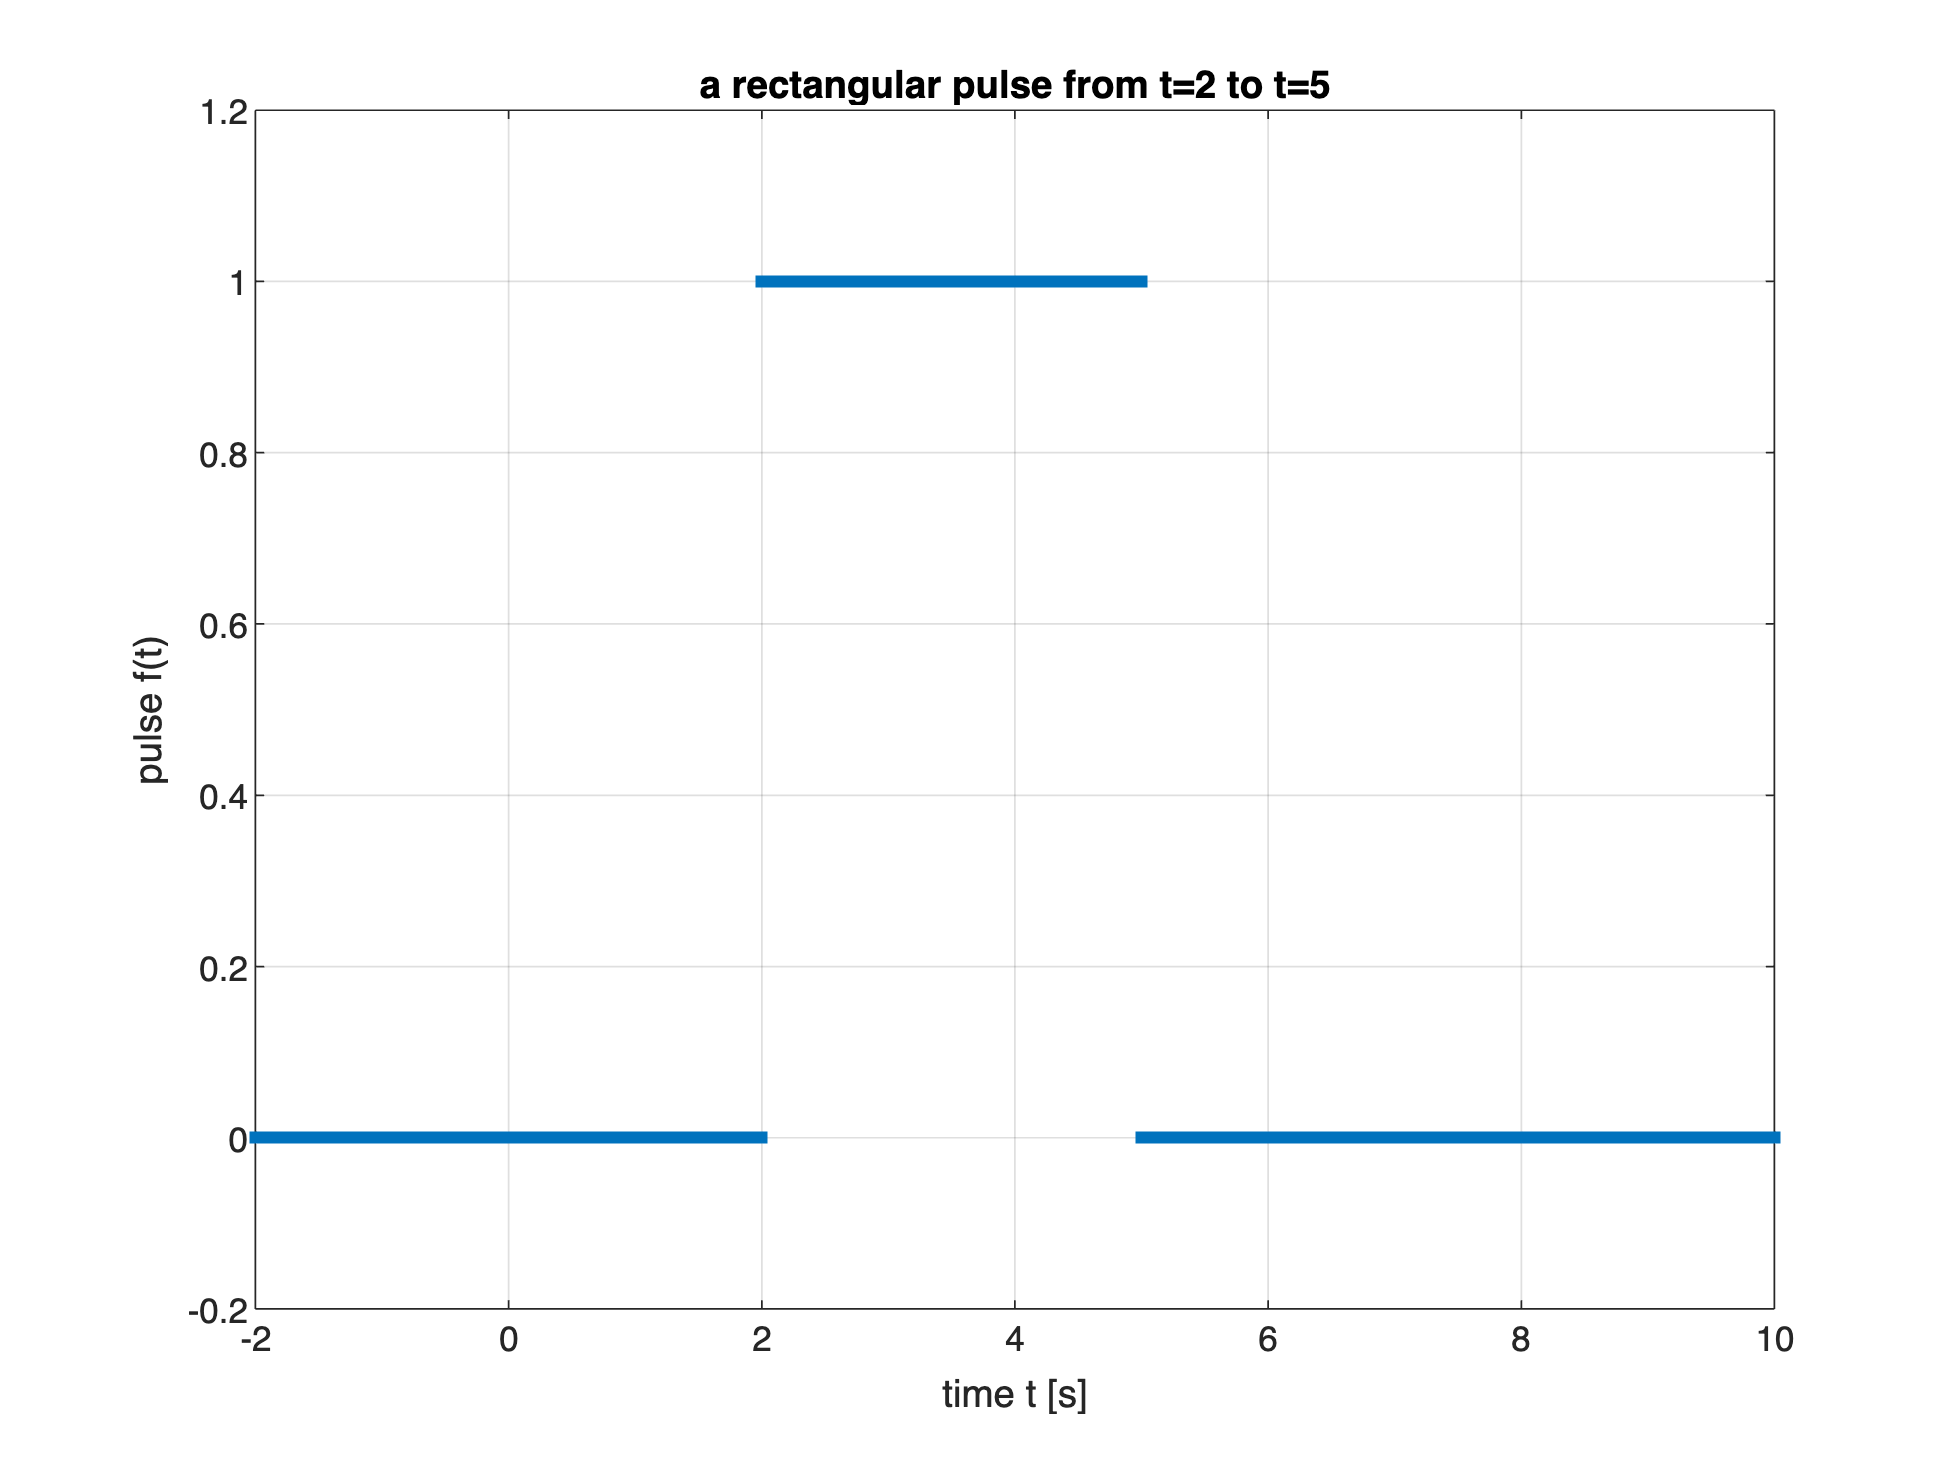

% let's plot the pulse
tVALs = (-2:1e-3:10);
plot(tVALs, f(sym(tVALs)), 'LineStyle', 'none', 'Marker', 'square',...
    'MarkerSize', 4, 'MarkerFaceColor', '#0072BD', 'MarkerEdgeColor', '#0072BD');

% fplot(f, [-2, 10], 'LineWidth', 3);
grid on
title('a rectangular pulse from t=2 to t=5')
xlabel('time t [s]');
ylabel('pulse f(t)');
ylim([-0.2, 1.2]);


% the corresponding Laplace transform
F(s) = collect(laplace(f, t, s), s)

$$F(s) = \frac{{\mathrm{e}}^{-2\,s}-{\mathrm{e}}^{-5\,s}}{s}$$

Another example:

  
$$f(t) = \left[ 3 e^{-0.75 t} \sin \left(16 t +\frac{\pi}{3}\right) \right] \cdot 1(t) \;, \quad g(t) = f\left(t- 1.5 \right) \cdot 1(t-1.5) \;\Longrightarrow \; 
g(t) = \left[ 3\, e^{-0.75 (t-1.5)} \sin \left(16 (t-1.5) +\frac{\pi}{3}\right) \right] \cdot 1(t-1.5)$$


clear variables

syms t s 
f(t) = ( 3 * exp(-0.75*t) * sin(16*t+pi/3) )*heaviside(t)

$$f(t) = 3\,\sin\left(16\,t+\frac{\pi }{3}\right)\,{\mathrm{e}}^{-\frac{3\,t}{4}}\,\mathrm{heaviside}\left(t\right)$$


T = sym(1.5); % the delay

% the delayed function
g(t) = f(t-T) % <<<<<<<-- Pay attention to the notation!  <<<<<<<-- 

$$g(t) = 3\,\mathrm{heaviside}\left(t-\frac{3}{2}\right)\,\sin\left(16\,t+\frac{\pi }{3}-24\right)\,{\mathrm{e}}^{\frac{9}{8}-\frac{3\,t}{4}}$$

g_ALT(t) = ( 3*exp(-0.75*(t-T)) * sin(16*(t-T)+pi/3) )* heaviside(t-T)

$$g\_ALT(t) = 3\,\mathrm{heaviside}\left(t-\frac{3}{2}\right)\,\sin\left(16\,t+\frac{\pi }{3}-24\right)\,{\mathrm{e}}^{\frac{9}{8}-\frac{3\,t}{4}}$$

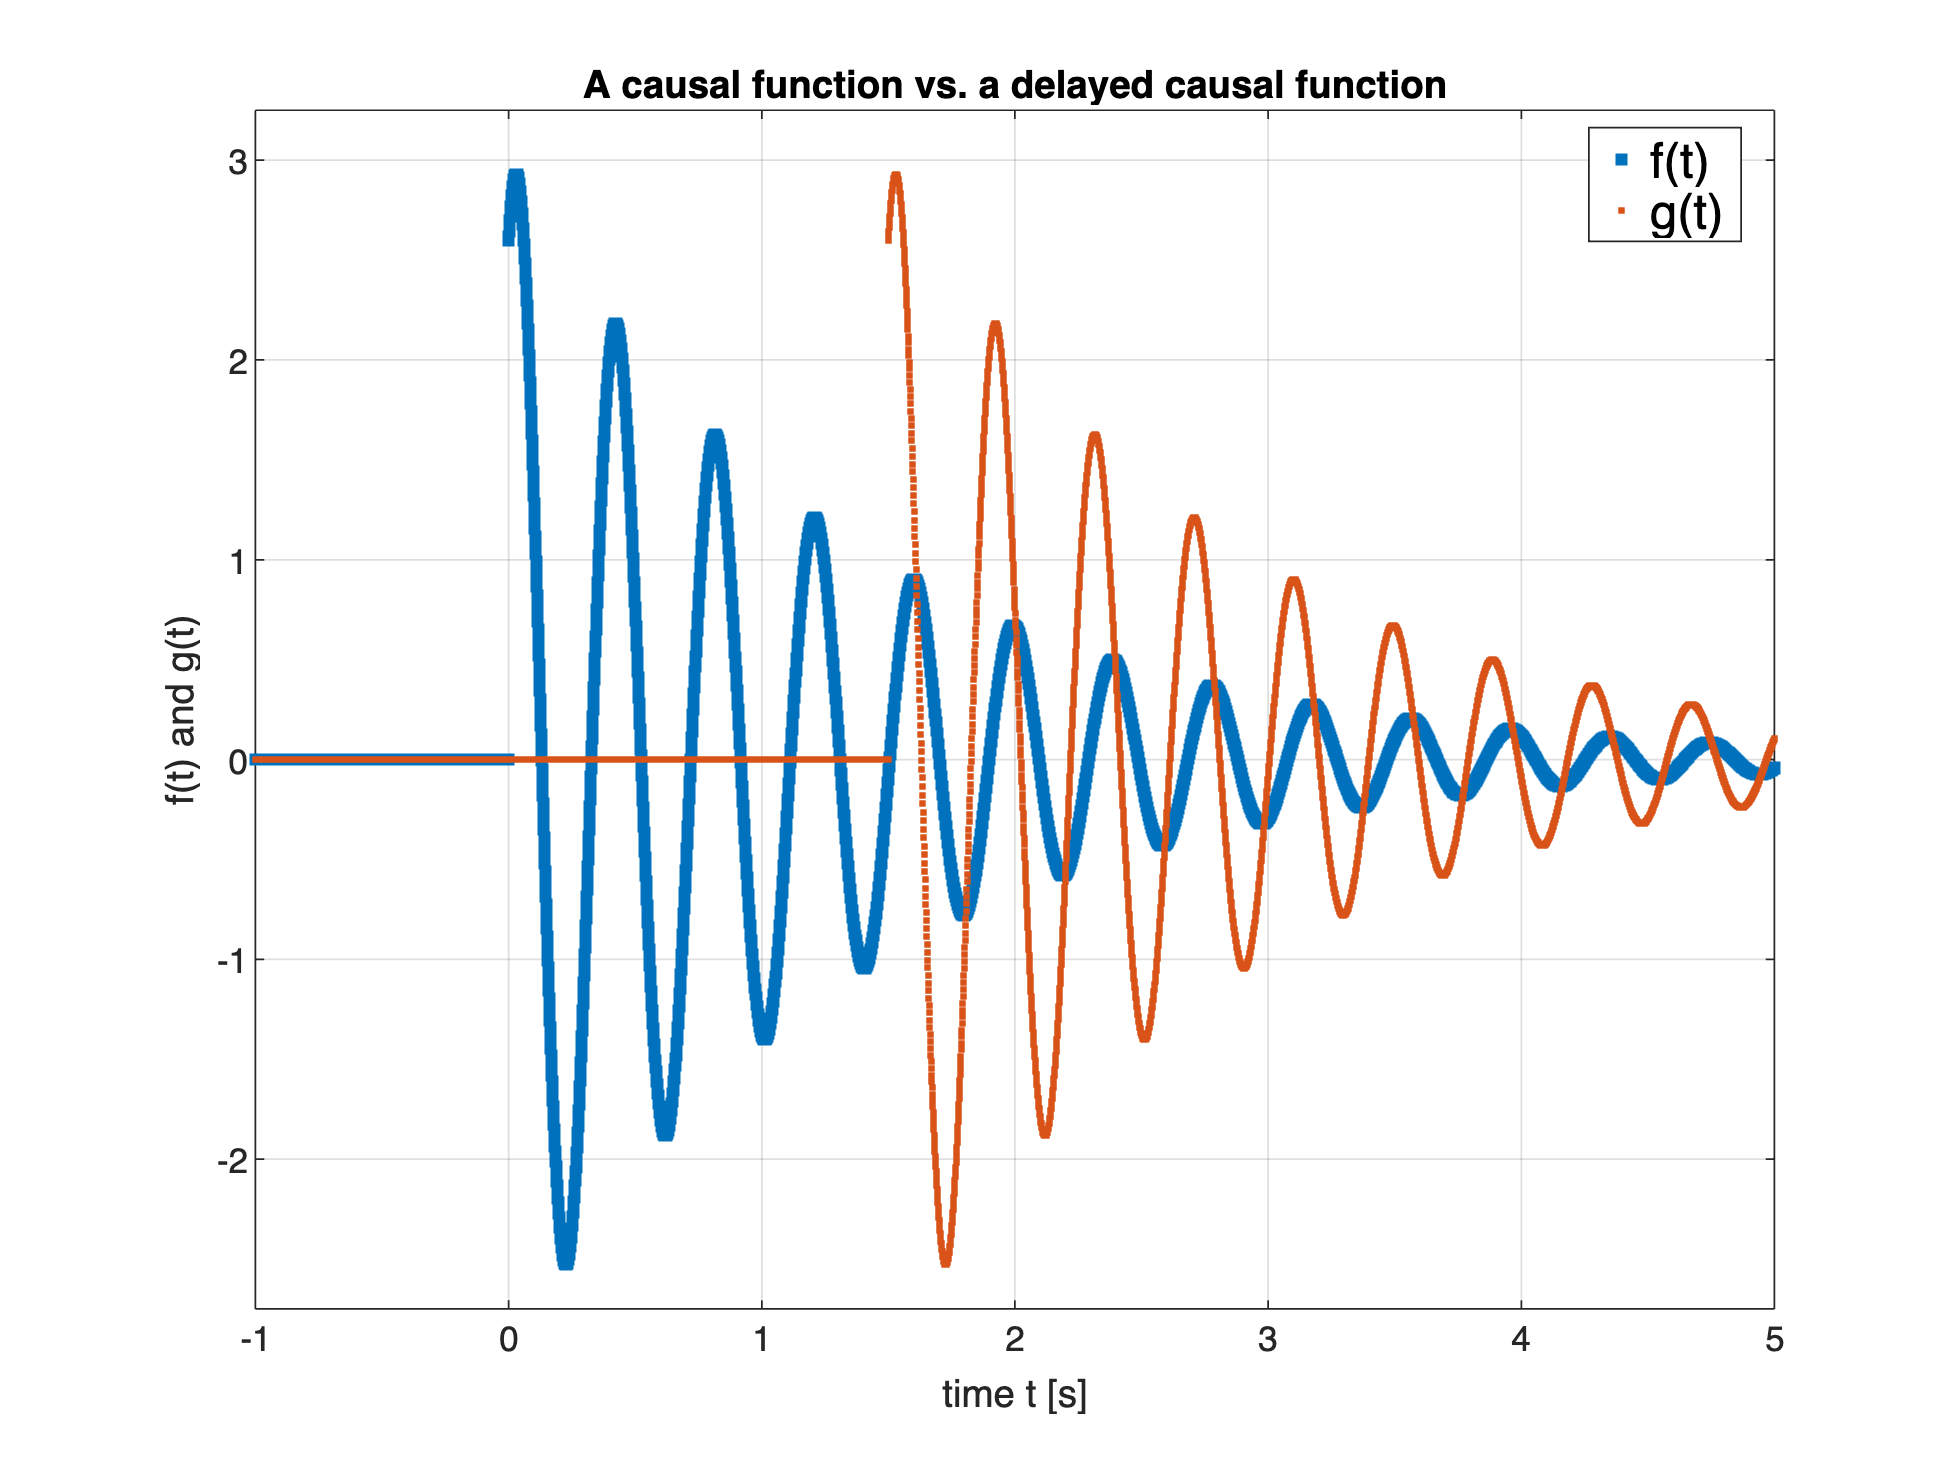

% let's draw both the functions f and g
tVALs = (-1:1e-3:5);
plot(tVALs, f(sym(tVALs)), 'LineStyle', 'none', 'Marker', 'square',...
    'MarkerSize', 4, 'MarkerFaceColor', '#0072BD', 'MarkerEdgeColor', '#0072BD');
hold on; grid on;
plot(tVALs, g(sym(tVALs)), 'LineStyle', 'none', 'Marker', 'square',...
    'MarkerSize', 2, 'MarkerFaceColor', '#D95319', 'MarkerEdgeColor', '#D95319');
hold off
xlabel('time t [s]');
ylabel('f(t) and g(t)');
legend('f(t)', 'g(t)','Location', 'best', 'FontSize', 14)
title('A causal function vs. a delayed causal function')
ylim([-2.75, 3.25])

#### Convolution

 The convolution of causal functions $f(t)$ and $g(t)$ is the causal function $h(t)$, defined as follows:


$$h := f*g \; \longleftrightarrow \; h(t) = \int_{0}^{t} f(\tau) g(t-\tau)\, d\tau$$


- **Note**: same as  $h(t) = \displaystyle \int_{0}^{t} f(t-\tau) g(\tau)\, d\tau$, i.e $f * g = g * f$


$$H(s) = \mathcal{L} \left(f * g \right) = F(s) \, G(s)$$


- The (very great) importance of this property will soon become clear (refer to **Part** **2, pp. 27-32** of the course material).

- Laplace transform turns convolution in time domain into multiplication in the frequency domain!

## The Inverse Laplace Transform

Given a Laplace transform $F(s)$, the **unique** corresponding **causal** **function** $f(t)$ can be recovered via:


$$f(t) = \frac{1}{2 \pi j} \int_{\sigma-j \infty}^{\sigma+j \infty}\, F(s)\, e^{st}\, ds$$


where $\sigma$ is large enough that $F(s)$ is defined for $\text{Re}\left(s\right) \ge \sigma$.

**Luckily, we do not use that formula! Instead, we will use the Symbolic Math Toolbox command ilaplace!**

help ilaplace

--- help for sym/ilaplace ---

 sym/ilaplace - Inverse Laplace transform
    This MATLAB function returns the Inverse Laplace Transform of F.

    Syntax
      f = ilaplace(F)
      f = ilaplace(F,transVar)
      f = ilaplace(F,var,transVar)

    Input Arguments
      F - Input
        symbolic expression | symbolic function | symbolic vector |
        symbolic matrix
      var - Independent variable
        s (default) | symbolic variable | symbolic expression |
        symbolic vector | symbolic matrix
      transVar - Transformation variable
        t (default) | x | symbolic variable | symbolic expres

### Important Remark

The **functions** in the time domain $f(t)$, with which we will deal, will always be 

- **causal** functions,

- **piecewise** **continuous** functions,

- they contain **no** **impulses** **at the time **$t=0$

Thus, the corresponding **Laplace** **transforms** $F(s)$ will always be **rational** **polynomial** **functions**


$$F(s) = \frac{b_m s^m +b_{m-1} s^{m-1}+ \cdots +b_1 s + b_0}{a_n s^n +a_{n-1} s^{n-1} + \cdots +a_1 s + a_0} = \frac{N(s)}{D(s)} \qquad \forall i \, a_i \in \mathbb{R},\; \forall j\, b_j \in \mathbb{R}$$


Furthermore, the degree of the numerator polynomial will be less than that of the denominator polynomial:  $m < n$.

### Computation of the Inverse Laplace Transform "by Hand": Sum of Partial Fractions

For the sake of completeness, we present the classical approach for determining the inverse Laplace transform.

Starting from a Laplace transform $F(s)$ that is a strictly proper rational function, it is **always** possible to express the function as a sum of partial fractions:


$$\begin{array}{rcl}
F(s) &=& \displaystyle \frac{C_{1,1}}{(s-p_1)} + \cdots +\frac{C_{1,n_{1}}}{(s-p_1)^{n_1}} + 
 \displaystyle \frac{C_{2,1}}{(s-p_2)} + \cdots +\frac{C_{2,n_{2}}}{(s-p_2)^{n_2}} +  \cdots +\displaystyle \frac{C_{q,1}}{(s-p_q)} + \cdots +\frac{C_{q,n_{q}}}{(s-p_q)^{n_q}}
\end{array} $$


where $C_{i,\,j} \in \mathbb{C}\,,\quad i=1,\,2,\,\ldots,\,q \;,\quad  j=1,\,2,\,\ldots,\, n_i $ and $\sum_{i=1}^{q} n_i = n$.

Owing to the linearity of the inverse Laplace transform, the time domain function we are looking for will be the linear combination of elementary exponential functions:


$$\mathcal{L}^{-1}\left(F(s) \right) = \displaystyle \sum_{i=1}^{q} \sum_{j=1}^{n_i} \mathcal{L}^{-1} \left[\displaystyle \frac{C_{i,j}}{(s-p_i)^{j}} \right] \; \Longrightarrow \;
\mathcal{L}^{-1}\left(F(s) \right) = \displaystyle \sum_{i=1}^{q} \sum_{j=1}^{n_i} \displaystyle \frac{C_{i,j}}{(j-1)!}\,t^{j-1}\,e^{p_i\,t} \cdot 1(t)$$


How to calculate the $C_{i,j}$ coefficients?


$$C_{i,\,j} = \frac{1}{\left(n_i-j \right) ! }\, \lim_{s \to  p_i} \left\{ \frac{d^{(n_i-j)}\,}{d \, s^{(n_i-j)}} \left[ F(s) \left(s-p_i\right)^{n_i}\right] \right\}$$


**Luckily, we do not use that formula! Instead, we will use the Symbolic Math Toolbox command ilaplace!**

### The Inverse Laplace Transform using MATLAB: Examples

#### A First Example

Given the Laplace transform 


$$F(s) = \displaystyle \frac{5\,s+3}{s^3+5\,s^2+8\,s+4}$$


determine the corresponding causal function $f(t)$ (i.e., the inverse Laplace transform)

clear variables

syms t s 

F(s) = (5*s+3)/(s^3+5*s^2+8*s+4)

$$F(s) = \frac{5\,s+3}{s^{3}+5\,s^{2}+8\,s+4}$$

We can simplify and factorise the rational expression, by applying the command `simplify`

F(s) = simplify(F)

$$F(s) = \frac{5\,s+3}{\left(s+1\right)\,{\left(s+2\right)}^{2}}$$

The inverse Laplace transform can be determined as follows:

f(t) = ilaplace(F, s, t)

$$f(t) = 2\,{\mathrm{e}}^{-2\,t}-2\,{\mathrm{e}}^{-t}+7\,t\,{\mathrm{e}}^{-2\,t}$$

#### Important Remark on Notation

As pointed out previously in this live script, often in the evaluation of Laplace transforms and inverse transforms the symbolic math engine does not insert any Heaviside function.

#### More Examples

Given the Laplace transform 


$$F(s) = \frac{2}{s^2 + 2 s + 2}\cdot e^{-2\,s}$$


determine the corresponding causal function $f(t)$ (i.e., the inverse Laplace transform). 

**Note**: According to the Laplace transform properties, this is the Laplace transform of a delayed causal function.

clear variables

syms t s

F(s) = (2/(s^2+2*s+2))*exp(-2*s)

$$F(s) = \frac{2\,{\mathrm{e}}^{-2\,s}}{s^{2}+2\,s+2}$$


f(t) = ilaplace(F, s, t)

$$f(t) = 2\,\mathrm{heaviside}\left(t-2\right)\,\sin\left(t-2\right)\,{\mathrm{e}}^{2-t}$$

**Note**: This time the Heaviside function is needed!

Given the Laplace transform 


$$F(s) = \frac{\left(2\,\sqrt{3}+4\right)\,s^3+\left(6\,\sqrt{3}+20 \right)\,s^2+\left(14\,\sqrt{3}+92\right)\,s+ \left(10\,\sqrt{3}+108 \right)}{s^4+4\,s^3+26\,s^2+44\,s+85}$$


determine the corresponding causal function $f(t)$

clear variables

syms t s

F(s) = (sym(2*sym(sqrt(3))+4)*s^3+sym(6*sym(sqrt(3))+20)*s^2+sym(14*sym(sqrt(3))+92)*s+sym(10*sym(sqrt(3))+108))/(s^4+4*s^3+26*s^2+44*s+85)

$$F(s) = \frac{\left(2\,\sqrt{3}+4\right)\,s^{3}+\left(6\,\sqrt{3}+20\right)\,s^{2}+\left(14\,\sqrt{3}+92\right)\,s+10\,\sqrt{3}+108}{s^{4}+4\,s^{3}+26\,s^{2}+44\,s+85}$$


f(t) = ilaplace(F, s, t)

$$f(t) = 4\,\cos\left(2\,t\right)\,{\mathrm{e}}^{-t}+2\,\sqrt{3}\,{\mathrm{e}}^{-t}\,\left(\cos\left(4\,t\right)+\sin\left(4\,t\right)\,\left(\frac{\sqrt{3}\,\left(2\,\sqrt{3}+8\right)}{24}-\frac{1}{4}\right)\right)$$


ft1 = simplify(ilaplace(F, s, t), 10)

$$ft1 = 2\,{\mathrm{e}}^{-t}\,\left(2\,\cos\left(2\,t\right)+2\,\sin\left(4\,t+\frac{\pi }{3}\right)\right)$$


ft2 = simplify(ilaplace(F, s, t), 100)

$$ft2 = 4\,{\mathrm{e}}^{-t}\,\left(\cos\left(2\,t\right)+\sin\left(4\,t+\frac{\pi }{3}\right)\right)$$

### Zeros and Poles of a Rational Laplace Transform

Consider a Laplace transform tha is a rational function of the complex variable $s$ as, for example   $F(s) = \displaystyle \frac{5\,s+3}{s^3+5\,s^2+8\,s+4}$

How to determine **zeros** and **poles** of the rational function in MATLAB?

clear variables

syms t s 

F(s) = (5*s+3)/(s^3+5*s^2+8*s+4)

$$F(s) = \frac{5\,s+3}{s^{3}+5\,s^{2}+8\,s+4}$$

To find the poles of $F(s)$ simply sue the command `poles`:

pSET = poles(F, s)

$$pSET = \left(\begin{array}{c} -2\\ -1 \end{array}\right)$$

What about the **order** of each **pole**?

[pSET, Np_SET] = poles(F, s) %

$$pSET = \left(\begin{array}{c} -2\\ -1 \end{array}\right)$$

$$Np\_SET = \left(\begin{array}{c} 2\\ 1 \end{array}\right)$$

How to determine the **zeros of a rational Laplace transform**? There is no devoted command. You have to use the `solve` command:

zSET = solve(F, s)

$$zSET = -\frac{3}{5}$$

Thus you obtain a symbolic vector containing the zeros, each one with its multiplicity.

#### Important Remark on Zeros of a Rational Laplace Transform

Pay attention: the command `solve` provides explicit solution usually for polynomial equations up to the degree $2$. If you want an explicit solution of a polynomial equation with higher degree, you have to use the following sintax for the command solve:

G(s) = 3*((s+3)^3*(s-1))/((s+10)^2*(s-5)^3)

$$G(s) = \frac{3\,\left(s-1\right)\,{\left(s+3\right)}^{3}}{{\left(s-5\right)}^{3}\,{\left(s+10\right)}^{2}}$$


[pSET, nSET] = poles(G, s)

$$pSET = \left(\begin{array}{c} -10\\ 5 \end{array}\right)$$

$$nSET = \left(\begin{array}{c} 2\\ 3 \end{array}\right)$$


zSET = solve(G, s, "MaxDegree",4)

$$zSET = \left(\begin{array}{c} -3\\ -3\\ -3\\ 1 \end{array}\right)$$

For details, refer to

doc sym/solve

## Theorems on the Laplace Transform

- Can we determine the **initial** **value** of a time-domain function **from** its **Laplace** **transform**?

- Can we determine the **steady-state value** of a time-domain function **from** its **Laplace** **transform**?

### Initial Value Theorem

Given a Laplace transform $F(s)$ that is a strictly proper rational function, the following property holds


$$\lim_{t \to 0} f(t) = \lim_{s \to +\infty} s\,F(s)$$


- You can analyse the time behaviour of $f(t)$  at $t=0$ directly from its Laplace transform $F(s)$, without computing the inverse Laplace transform!

#### An Application Example

Given the Laplace transform $F(s) = \displaystyle \frac{5\,s+3}{(s+1)\,(s+2)^2}$, determine $f(0)$ without computing the inverse Laplace transform:

clear variables
syms s t

F(s) = (5*s+3)/(s+1)/(s+2)^2

$$F(s) = \frac{5\,s+3}{\left(s+1\right)\,{\left(s+2\right)}^{2}}$$


f0 = limit(s*F, s, +Inf)

$$f0 = 0$$

Let's verify:

f(t) = ilaplace(F,s, t)

$$f(t) = 2\,{\mathrm{e}}^{-2\,t}-2\,{\mathrm{e}}^{-t}+7\,t\,{\mathrm{e}}^{-2\,t}$$

f(0)

$$ans = 0$$

### Final Value Theorem

Given a Laplace transform $F(s)$ that is a rational function, 

- if all the **poles** of $F(s)$ are in the** left open half-plane**, with at most one simple pole in the origin,  then the following identity holds and the two limits assume the same finite value.


$$\lim_{t \to +\infty} f(t) = \lim_{s \to 0} s \cdot F(s)$$


#### Important Remark

Pay attention to the assumptions about the poles of the Laplace transform! They are crucial!

#### Application Example

Given the Laplace transform $F(s) = \displaystyle \frac{5\,s+3}{s\,(s+1)\,(s+2)^2}$, determine, if possible,  $f_{\infty} = \lim_{t \to +\infty} f(t) $

clear variables
syms s t

F(s) = (5*s+3)/s/(s+1)/(s+2)^2;

Let's verify if the Final Value Theorem's assumptions are met:

- determine the poles of $F(s)$;

- verify that all the poles belong to the left open half-plane, with at most one simple pole at the origin.

[pF, n_pF] = poles(F, s) % poles and corresponding multiplicity

$$pF = \left(\begin{array}{c} -2\\ -1\\ 0 \end{array}\right)$$

$$n\_pF = \left(\begin{array}{c} 2\\ 1\\ 1 \end{array}\right)$$

% --- 1st check: is there a pole at s=0? ---
pole0ID = isAlways(pF==sym(0));
if any(pole0ID)
    pole0 = true;
    p0M = isAlways(n_pF(pole0ID)==1);
else
    pole0 = false;
    p0M = false;
end
if (pole0 && p0M) || ~(pole0)
    p0OK = true;
else
    p0OK = false;
end
% --- 1st check: is there a pole at s=0? ---


% ---- 2nd check: Do all the remainig poles have negative real part? ---- 
if pole0
    poles2analyse = not(pole0ID);
else
    poles2analyse = true(size(pF));
end
pN_OK = all(isAlways(real(pF(poles2analyse))<sym(0)));
% final check

if (pN_OK && p0OK)
    disp('The Final Value Theorem''s assumptions are met!');
    disp('You can apply the Final Value Theorem!')

    limf_infty = limit(s*F, s , 0)

    % let's verify, by comparison with the inverse Laplace transform
    f(t) = ilaplace(F, s, t);
    f2infty = limit(f, t, +Inf)

else
    disp('*** The Final Value Theorem''s assumptions are NOT met! ***');
    disp('*** You CANNOT apply the Final Value Theorem! ***')
end

The Final Value Theorem's assumptions are met!


You can apply the Final Value Theorem!


$$limf\_infty = \frac{3}{4}$$

$$f2infty = \frac{3}{4}$$